## Étape 1 : Collecte des données via l' API de FRED

API KEY  : `75033e7e3144495275a0ffd998e359a9`

clear; clc;

%%% Téléchargement des données
% Clé API FRED
apiKey = '75033e7e3144495275a0ffd998e359a9';  % Remplace par ta clé API FRED

% Définir les séries FRED pour les variables
seriesCode_y1 = 'DEXCAUS';  % Taux de change CAD/USD
seriesCode_y2_canada = 'IRLTLT01CAM156N';  % Taux d'intérêt Canada 
seriesCode_y2_us = 'IRLTLT01USM156N';  % Taux d'intérêt US
seriesCode_y3 = 'DCOILWTICO';  % Variation du prix du pétrole (WTI) 
seriesCode_y4 = 'CANCPIALLMINMEI';  % Inflation Canada
seriesCode_y5 = 'CPIAUCSL';  % Inflation US

% Plage de dates
startDate = '2005-01-01';
endDate = '2025-01-01';

% Fonction pour télécharger les données FRED
function data = getData(seriesCode, startDate, endDate, apiKey)
    url = ['https://api.stlouisfed.org/fred/series/observations?', ...
           'series_id=', seriesCode, ...
           '&api_key=', apiKey, '&file_type=json', ...
           '&observation_start=', startDate, '&observation_end=', endDate];
    data = webread(url);
end

% Télécharger les données
data_y1 = getData(seriesCode_y1, startDate, endDate, apiKey);  % Taux de change CAD/USD
data_y2_canada = getData(seriesCode_y2_canada, startDate, endDate, apiKey);  % Taux d'intérêt Canada
data_y2_us = getData(seriesCode_y2_us, startDate, endDate, apiKey);  % Taux d'intérêt US
data_y3 = getData(seriesCode_y3, startDate, endDate, apiKey);  % Variation du prix du pétrole (WTI)
data_y4 = getData(seriesCode_y4, startDate, endDate, apiKey);  % Inflation Canada
data_y5 = getData(seriesCode_y5, startDate, endDate, apiKey);  % Inflation US



## **Étape 2 :  Prétraitement et transformation**


%% Extraction et traitement des données

% 1. Création des timetables individuels avec vérification des données
createTT = @(data, varName) timetable(...
    datetime({data.observations.date}', 'InputFormat', 'yyyy-MM-dd'), ...
    str2double({data.observations.value})', ...
    'VariableNames', {varName});

% Création des tables pour chaque série
tt_y1 = createTT(data_y1, 'taux_change');
tt_y2_canada = createTT(data_y2_canada, 'taux_interet_can');
tt_y2_us = createTT(data_y2_us, 'taux_interet_us');
tt_y3 = createTT(data_y3, 'prix_petrole');
tt_y4 = createTT(data_y4, 'inflation_can');
tt_y5 = createTT(data_y5, 'inflation_us');

% 2. Calcul de la variation du pétrole (différence logarithmique)
tt_y3.value = [NaN; diff(log(tt_y3.prix_petrole))]; % Variation log en %

% 3. Synchronisation des données (sur la fréquence mensuelle)
freq = 'monthly';
method = 'lastvalue'; % Prend la dernière observation du mois

% Retiming et synchronisation
TT = synchronize(...
    retime(tt_y1, freq, method), ...
    retime(tt_y2_canada, freq, method), ...
    retime(tt_y2_us, freq, method), ...
    retime(tt_y3, freq, method), ...
    retime(tt_y4, freq, method), ...
    retime(tt_y5, freq, method));

% 4. Calcul du différentiel de taux d'intérêt
TT.diff_taux = TT.taux_interet_can - TT.taux_interet_us;

% 5. Renommage des colonnes et sélection finale
TT = TT(:, {'taux_change', 'diff_taux', 'prix_petrole', 'inflation_can', 'inflation_us'});
TT.Properties.VariableNames = {'y1', 'y2', 'y3', 'y4','y5'};

% 6. Nettoyage des données manquantes
TT = rmmissing(TT); % Supprime les lignes avec NaN

%% Vérification des résultats
summary(TT);


TT: 240x5 timetable

Row Times:

    Time: datetime

Variables:

    y1: double
    y2: double
    y3: double
    y4: double
    y5: double

Statistics for applicable variables and row times:

            NumMissing          Min                   Median                   Max                    Mean                    Std      

    Time        0           01-Jan-2005        16-Dec-2014 12:00:00        01-Dec-2024        16-Dec-2014 05:00:00        50715:51:16  
    y1          0                0.9486                      1.2397             1.4400                      1.1966             0.1363  
    y2          0               -1.2285                     -0.2850             0.5257                     -0.3187             0.3166  
    y3          0               19.2300                     70.4650           139.9600                     72.1860            21.2776  
    y4          0               83.1973                     99.4338           128.0748                    101.3119           

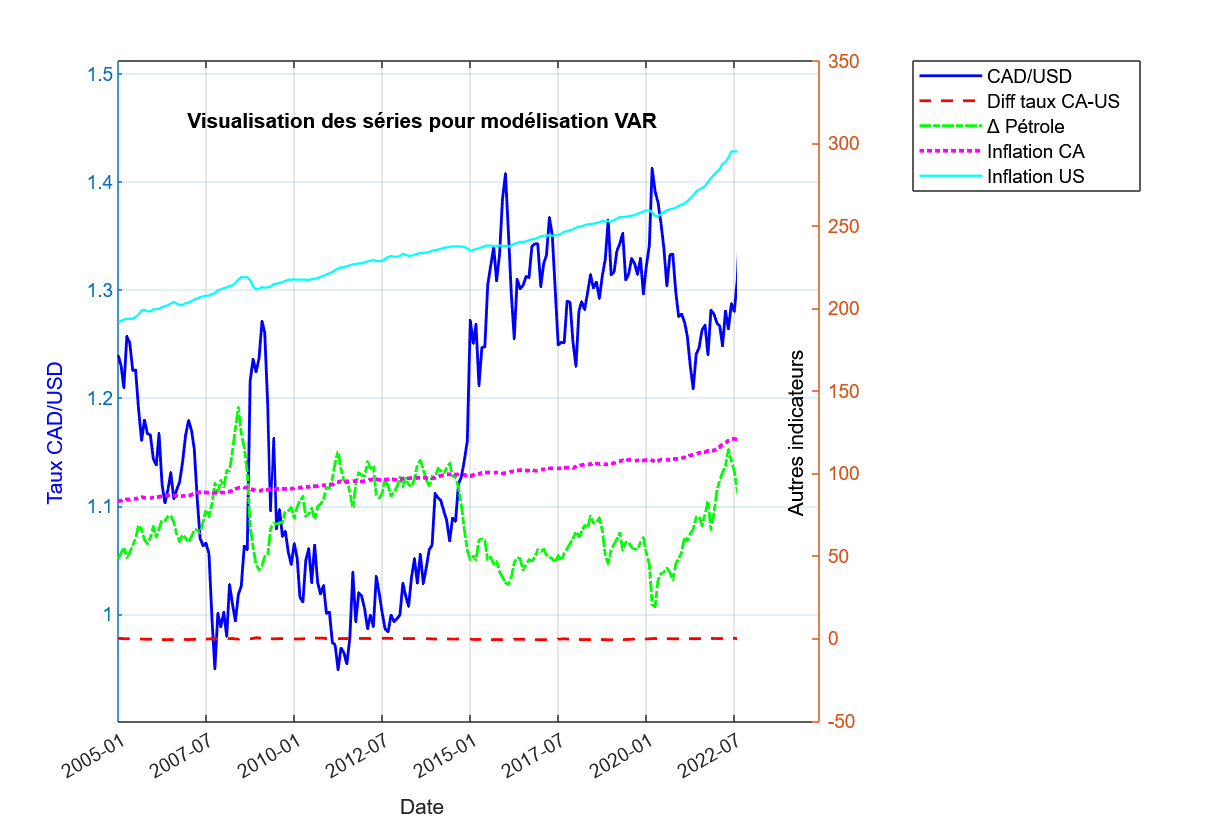

%% Visualisation avancée des séries temporelles
figure('Position', [100 100 900 600]); % Taille personnalisée

% 1. Taux de change CAD/USD (axe Y de gauche)
yyaxis left;
p1 = plot(TT.Time, TT.y1, 'b-', 'LineWidth', 1.5);
ylabel('Taux CAD/USD', 'Color', 'b');
ylim([min(TT.y1)*0.95 max(TT.y1)*1.05]);

% 2. Autres séries (axe Y de droite)
yyaxis right;
hold on;
p2 = plot(TT.Time, TT.y2, 'r--', 'LineWidth', 1.5);
p3 = plot(TT.Time, TT.y3, 'g-.', 'LineWidth', 1.5); 
p4 = plot(TT.Time, TT.y4, 'm:', 'LineWidth', 2);
p5 = plot(TT.Time, TT.y5, 'c-', 'LineWidth', 1.2);
ylabel('Autres indicateurs', 'Color', 'k');

% Configuration du graphique
title('Visualisation des séries pour modélisation VAR', 'FontSize', 14);
xlabel('Date', 'FontSize', 12);
grid on;

% Légende améliorée
legend([p1 p2 p3 p4 p5], ...
    {'CAD/USD', 'Diff taux CA-US', ...
     'Δ Pétrole', 'Inflation CA', 'Inflation US'}, ...
    'Location', 'bestoutside', 'FontSize', 10);

% Ajustement des axes
datetick('x', 'yyyy-mm', 'keeplimits');
set(gca, 'FontSize', 10, 'XMinorTick', 'on');

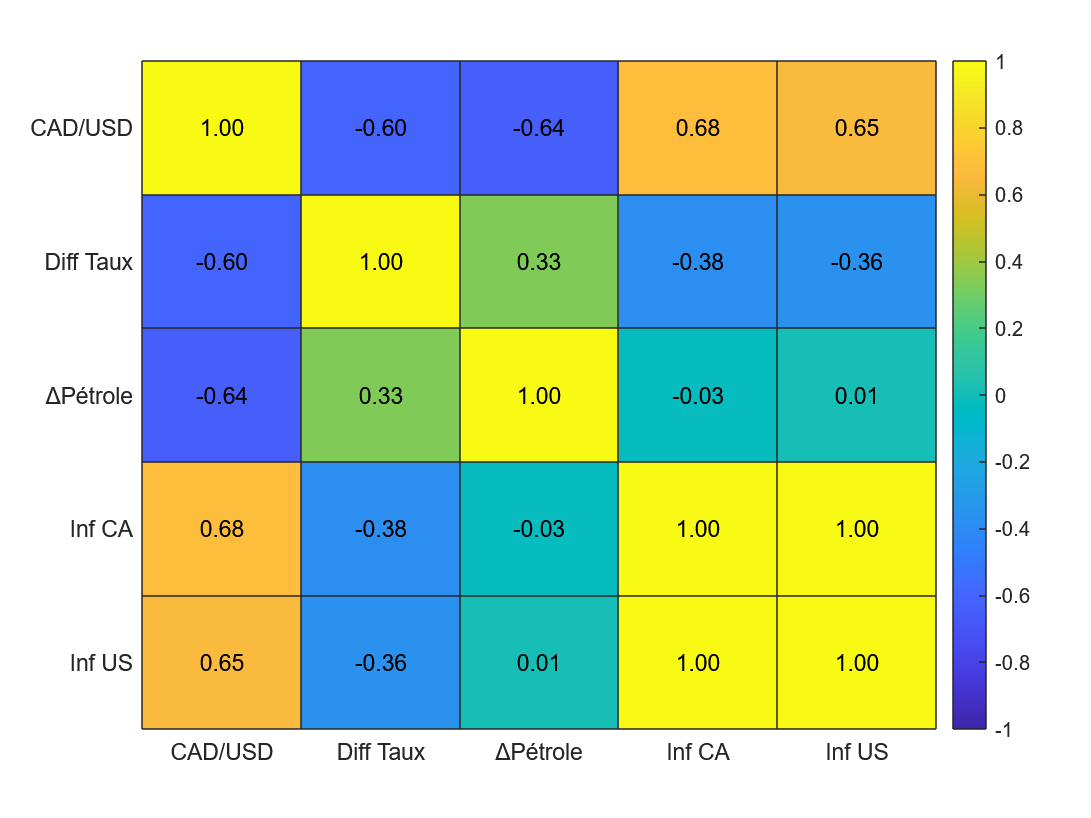


%% Préparation des données
% Suppression des lignes avec NaN
TT_clean = rmmissing(TT(:,{'y1','y2','y3','y4','y5'}));

% Vérification
if height(TT_clean) < 10
    warning('Moins de 10 observations après nettoyage !');
    disp(sum(ismissing(TT(:,{'y1','y2','y3','y4','y5'}))));
end

%% Création de la heatmap de corrélation
figure('Position', [100 100 800 600]);

% 1. Calcul de la matrice de corrélation
corr_matrix = corr(TT{:, {'y1','y2','y3','y4','y5'}}, 'Rows', 'complete');

% 2. Création de la heatmap avec paramètres optimisés
h = heatmap({'CAD/USD','Diff Taux','ΔPétrole','Inf CA','Inf US'}, ...
            {'CAD/USD','Diff Taux','ΔPétrole','Inf CA','Inf US'}, ...
            corr_matrix);

% 3. Personnalisation avancée
h.Title = 'Matrice de Corrélation des Séries';
h.Colormap = parula; % Ou turbo, hot, cool, etc.
h.FontSize = 12;
h.ColorbarVisible = 'on';
h.CellLabelFormat = '%.2f'; % 2 décimales
h.CellLabelColor = 'k'; % Couleur texte noire

% 4. Ajustement des couleurs pour meilleur contraste
h.ColorLimits = [-1 1]; % Forcer l'échelle -1 à 1

## **Étape 3 :  Tests statistiques et estimation VAR**

- **Stationnarité :**

**                 Test ADF (détection de racines unitaires) + Test KPSS ( vérification de stationnarité autour d’une tendance).**

*Pourquoi ?* Ils testent des hypothèses inverses (ADF:H0=non-stationnarité, KPSS:H0=stationnarité), ce qui réduit les faux positifs.

- Pour le test de Dickey-Fuller Augmenté, on verifie d'abord s'il y a une tendance et une constante, pour choisir l'alternative à utiliser.

Nous allons donc faire une régression sur le temps t pour chacune de nos séries et tester la significativité de la constante et de la tendance.

% Les séries sont stockées dans la timetable appelée 'TT'
% chaque colonne = une série (ex: TT.y1, TT.y2, etc.)

% --- Paramètres de base ---
n = height(TT); % nombre d'observations (lignes)
p = width(TT);  % nombre de séries (colonnes)
t = (1:n)';     % vecteur du temps (indice de la timetable)

model_type = strings(p,1); % vecteur pour stocker le type de modèle ('CT', 'C' ou 'NC')

% --- Boucle sur chaque série ---
for j = 1:p
    % Extraire la série j de la timetable
    serie = TT{:, j};
    
    % Afficher l'analyse de la série
    fprintf('\n--- Analyse de la série %d ---\n', j);
    
    % Matrice des variables explicatives (constante et tendance)
    X = [ones(n,1), t];  % 1 pour la constante, t pour la tendance
    
    % Régression avec "regress"
    [b, bint, r, rint, stats] = regress(serie, X);
    
    % Extraction des p-valeurs pour tester la significativité des coefficients
    p_val_beta0 = 1 - tcdf(abs(b(1)/sqrt((bint(1,2)-bint(1,1))/2)), n-2); % p-value pour la constante
    p_val_beta1 = 1 - tcdf(abs(b(2)/sqrt((bint(2,2)-bint(2,1))/2)), n-2); % p-value pour la tendance
    
    % Test de significativité des coefficients
    if p_val_beta1 < 0.05
        fprintf('=> Tendance significative détectée.\n Utiliser ADF avec constante + tendance.\n');
        model_type(j) = "CT"; % constante + tendance
    elseif p_val_beta0 < 0.05
        fprintf('=> Constante significative détectée.\n Utiliser ADF avec constante seule.\n');
        model_type(j) = "C";  % constante seule
    else
        fprintf('=> Ni constante ni tendance significative.\n Utiliser ADF sans constante ni tendance.\n');
        model_type(j) = "NC"; % ni constante ni tendance
    end
end


--- Analyse de la série 1 ---


=> Constante significative détectée.
 Utiliser ADF avec constante seule.



--- Analyse de la série 2 ---


=> Ni constante ni tendance significative.
 Utiliser ADF sans constante ni tendance.



--- Analyse de la série 3 ---


=> Constante significative détectée.
 Utiliser ADF avec constante seule.



--- Analyse de la série 4 ---


=> Tendance significative détectée.
 Utiliser ADF avec constante + tendance.



--- Analyse de la série 5 ---


=> Tendance significative détectée.
 Utiliser ADF avec constante + tendance.



% --- Résultat final ---
type_test = table(TT.Properties.VariableNames', model_type, 'VariableNames', {'Serie', 'Test_Type'});
resume = ['=== Résumé du type de test à faire pour chaque série ===: ' newline   evalc('disp(type_test)')];
disp(resume);

=== Résumé du type de test à faire pour chaque série ===: 
    Serie     Test_Type
    ______    _________

    {'y1'}      "C"    
    {'y2'}      "NC"   
    {'y3'}      "C"    
    {'y4'}      "CT"   
    {'y5'}      "CT"   




Maintenant que nous savons quelle alternative utliser pour chacune de nos séries, faisons le test ADF.

%%% Test ADF pour toutes nos séries
%%%% Etape 1 : Choix du nombre de retard (AIC) pour chaque série

function bestP = choisirARparAIC(serie, pMax, nomSerie)
    %% Version finale corrigée
    % 1. Validation des entrées
    if nargin < 3, nomSerie = 'Série anonyme'; end
    serie = rmmissing(serie); % Suppression des NaN
    if isempty(serie)
        error('Série %s vide après suppression des NaN', nomSerie);
    end
    
    % 2. Initialisation 
    results = struct();
    aic_values = nan(pMax+1, 1);
    succes = false(pMax+1, 1);
    
    % 3. Estimation AR
    for p = 0:pMax
        try
            Mdl = arima(p, 0, 0);
            [~,~,logL] = estimate(Mdl, serie, 'Display', 'off');

=== Ordres AR optimaux ===: 
        Série        Ordre_AR
    _____________    ________

    {'USDCAD'   }       1    
    {'Diff_Taux'}       2    
    {'Petrole'  }       2    
    {'Inf_CAN'  }       2    
    {'Inf_US'   }       4    




            
            if ~isempty(logL) && isfinite(logL)
                aic_values(p+1) = -2*logL + 2*(p+1);
                succes(p+1) = true;
            end
        catch
            continue; % Passe à l'ordre suivant en cas d'erreur
        end
    end
    
    % 4. Sélection du meilleur modèle
    valid_p = find(succes);
    if isempty(valid_p)
        warning('Aucun modèle valide pour %s', nomSerie);
        bestP = NaN;
        return;
    end
    
    [~, idx] = min(aic_values(valid_p));
    bestP = valid_p(idx) - 1;

end


%% Configuration
pMax = 12;
series = {'y1', 'y2', 'y3', 'y4', 'y5'};
noms = {'USDCAD', 'Diff_Taux', 'Petrole', 'Inf_CAN', 'Inf_US'};

%% Analyse avec gestion d'erreurs globale
best_orders = nan(length(series), 1);
for i = 1:length(series)
    try
        best_orders(i) = choisirARparAIC(TT_clean.(series{i}), pMax, noms{i});
    catch ME
        fprintf('Erreur principale sur %s : %s\n', noms{i}, ME.message);
    end
end


%% Affichage final
results = table(noms', best_orders, 'VariableNames', {'Série', 'Ordre_AR'});
ordres = ['=== Ordres AR optimaux ===: ' newline   evalc('disp(results)')];
disp(ordres);
%%%% Etape 2: Test ADF + KPSS en fonction du modèle détecté 

for j = 1:p
    serie = TT_clean{:, j}; 
    nomSerie = TT_clean.Properties.VariableNames{j};

--- Série y1 ---


Modèle détecté : C | Retards : 1


========== Résultats des tests ADF + KPSS ==========



ADF : H₀ non rejetée => Série NON STATIONNAIRE (p = 0.7790)


KPSS : H₀ rejetée => Série NON STATIONNAIRE (p = 0.0100)



--- Série y2 ---


Modèle détecté : NC | Retards : 2


========== Résultats des tests ADF + KPSS ==========



ADF : H₀ non rejetée => Série NON STATIONNAIRE (p = 0.2615)


KPSS : Non applicable (pas de constante ni tendance)



--- Série y3 ---


Modèle détecté : C | Retards : 2


========== Résultats des tests ADF + KPSS ==========



ADF : H₀ non rejetée => Série NON STATIONNAIRE (p = 0.3676)


KPSS : H₀ rejetée => Série NON STATIONNAIRE (p = 0.0100)



--- Série y4 ---


Modèle détecté : CT | Retards : 2


========== Résultats des tests ADF + KPSS ==========



ADF : H₀ non rejetée => Série NON STATIONNAIRE (p = 0.9728)


KPSS : H₀ rejetée => Série NON STATIONNAIRE (p = 0.0100)



--- Série y5 ---


Modèle détecté : CT | Retards : 4


========== Résultats des tests ADF + KPSS ==========



ADF : H₀ non rejetée => Série NON STATIONNAIRE (p = 0.9962)


KPSS : H₀ rejetée => Série NON STATIONNAIRE (p = 0.0100)



    modele = model_type(j);

    % Initialisation
    h_kpss = NaN; pValue_kpss = NaN;

    % ADF selon modèle
    switch modele
        case "CT"
            [h_adf, p_adf] = adftest(serie, 'model', 'TS', 'lags', best_orders(j));
            [h_kpss, p_kpss] = kpsstest(serie, 'Trend', true);
        case "C"
            [h_adf, p_adf] = adftest(serie, 'model', 'AR', 'lags', best_orders(j));
            [h_kpss, p_kpss] = kpsstest(serie, 'Trend', false);
        case "NC"
            [h_adf, p_adf] = adftest(serie, 'model', 'ARD', 'lags', best_orders(j));
    end

    % Texte explicatif
    fprintf('--- Série %s ---\n', nomSerie);
    fprintf('Modèle détecté : %s | Retards : %d\n', modele, best_orders(j));

    % Résultat ADF
    if h_adf == 1
        adf_txt = sprintf('ADF : H₀ rejetée => Série STATIONNAIRE (p = %.4f)', p_adf);
    else
        adf_txt = sprintf('ADF : H₀ non rejetée => Série NON STATIONNAIRE (p = %.4f)', p_adf);
    end

    % Résultat KPSS
    if isnan(h_kpss)
        kpss_txt = 'KPSS : Non applicable (pas de constante ni tendance)';
    elseif h_kpss == 0
        kpss_txt = sprintf('KPSS : H₀ non rejetée => Série STATIONNAIRE (p = %.4f)', p_kpss);
    else
        kpss_txt = sprintf('KPSS : H₀ rejetée => Série NON STATIONNAIRE (p = %.4f)', p_kpss);
    end


    fprintf('========== Résultats des tests ADF + KPSS ==========\n\n');

========== Résultats du test de Phillips-Perron (PP) ==========



--- Série y1 ---


Modèle utilisé : AR


=> PP : H₀ non rejetée => Série NON STATIONNAIRE (p = 0.7570)



========== Résultats du test de Phillips-Perron (PP) ==========



--- Série y2 ---


Modèle utilisé : ARD


=> PP : H₀ non rejetée => Série NON STATIONNAIRE (p = 0.4392)



========== Résultats du test de Phillips-Perron (PP) ==========



--- Série y3 ---


Modèle utilisé : AR


=> PP : H₀ non rejetée => Série NON STATIONNAIRE (p = 0.4606)



========== Résultats du test de Phillips-Perron (PP) ==========



--- Série y4 ---


Modèle utilisé : TS


=> PP : H₀ non rejetée => Série NON STATIONNAIRE (p = 0.9944)



========== Résultats du test de Phillips-Perron (PP) ==========



--- Série y5 ---


Modèle utilisé : TS


=> PP : H₀ non rejetée => Série NON STATIONNAIRE (p = 0.9990)




    % Affichage final
    fprintf('%s\n', adf_txt);
    fprintf('%s\n\n', kpss_txt);
end

##                   Analyse préliminaire des tests de stationnarité (ADF et KPSS)

Nous avons mené une analyse préliminaire de la stationnarité des séries économiques à l'aide des tests de racine unitaire ADF (Augmented Dickey-Fuller) et KPSS (Kwiatkowski-Phillips-Schmidt-Shin). Les résultats obtenus indiquent unanimement une absence de stationnarité pour l'ensemble des séries considérées :

- **y1 (Taux de change CAD/USD)** : Non stationnaire.

- **y2 (Différentiel de taux d'intérêt Canada–États-Unis)** : Non stationnaire (seul test ADF applicable).

- **y3 (Variation logarithmique du prix du pétrole)** : Non stationnaire.

- **y4 (Inflation Canada)** : Non stationnaire.

- **y5 (Inflation États-Unis)** : Non stationnaire.

Ces résultats sont particulièrement surprenants pour la série du prix du pétrole (`y3`), puisque celle-ci a été transformée en variation logarithmique (différence des logarithmes), une procédure généralement considérée comme suffisante pour rendre les séries économiques stationnaires. L'observation persistante de non-stationnarité pourrait être expliquée par plusieurs facteurs :

- **La présence éventuelle de ruptures structurelles non captées par les tests ADF et KPSS**. De telles ruptures structurelles sont courantes sur les marchés des matières premières, notamment en raison d'événements économiques ou géopolitiques.

- **Des effets de volatilité conditionnelle (hétéroscédasticité)**, fréquents sur les séries financières ou économiques comme les prix du pétrole.

- **Des comportements à long terme (persistance ou mémoire longue)** qui ne sont pas totalement éliminés par une simple différenciation logarithmique.

Afin de mieux comprendre et valider ces résultats, nous procéderons par la suite à une analyse complémentaire utilisant le test de Phillips-Perron (PP), reconnu pour sa robustesse face à la corrélation sérielle et à l'hétéroscédasticité. Cette étape supplémentaire permettra de confirmer ou nuancer ces premiers résultats, et ainsi d'établir des recommandations claires pour les étapes suivantes du processus de modélisation.

## **                Test de Phillips-Perron pour confimer les résultats**

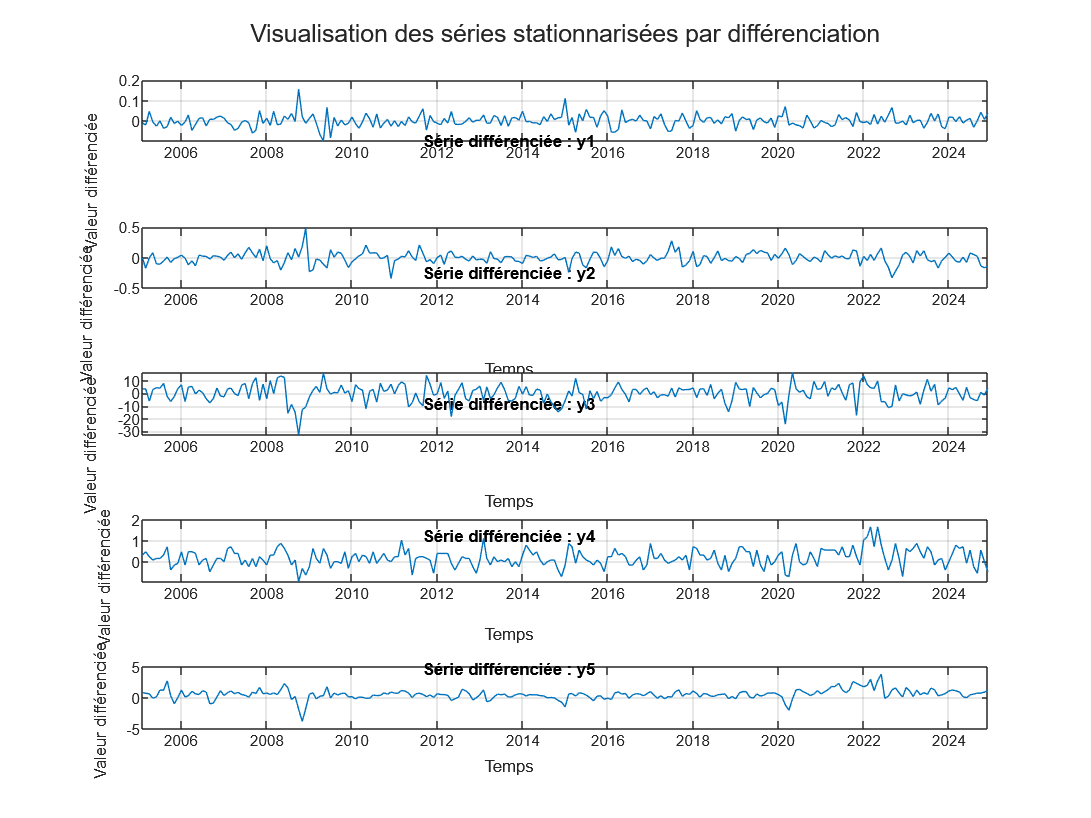

%%% Test PP pour toutes nos séries

for j = 1:p
    serie = TT_clean{:, j};
    nomSerie = TT_clean.Properties.VariableNames{j};
    modele = model_type(j);

    % Choix du modèle de tendance
    switch modele
        case "CT"
            model_pp = 'TS';  % constante + tendance
        case "C"
            model_pp = 'AR';  % constante seule
        case "NC"
            model_pp = 'ARD'; % sans constante ni tendance
    end

    % Test PP
    [h_pp, p_pp, stat_pp, cval_pp] = pptest(serie, 'model', model_pp, 'alpha', 0.05);

    % Affichage

    fprintf('========== Résultats du test de Phillips-Perron (PP) ==========\n\n');
    fprintf('--- Série %s ---\n', nomSerie);
    fprintf('Modèle utilisé : %s\n', model_pp);

    if h_pp == 1

        fprintf('=> PP : H₀ rejetée => Série STATIONNAIRE (p = %.4f)\n\n', p_pp);
    else
        fprintf('=> PP : H₀ non rejetée => Série NON STATIONNAIRE (p = %.4f)\n\n', p_pp);
    end
end

## **                Commentaire sur la stationnarité des séries**

Les tests de racine unitaire ADF (Augmented Dickey-Fuller), KPSS (Kwiatkowski-Phillips-Schmidt-Shin) et Phillips-Perron (PP) ont été appliqués aux séries temporelles considérées afin d’évaluer leur caractère stationnaire.

Les résultats montrent une convergence forte entre les trois tests :

toutes les séries sont identifiées comme **non stationnaires**.

- Le test ADF n'a pas permis de rejeter l'hypothèse nulle de racine unitaire pour la majorité des séries.

- Le test KPSS, dont l'hypothèse nulle est la stationnarité, a conduit au rejet de cette hypothèse, confirmant la non-stationnarité.

- Le test PP, qui corrige les faiblesses du test ADF en présence d'autocorrélation ou d'hétéroscédasticité, a confirmé les résultats de l'ADF en identifiant également une non-stationnarité des séries.

Ce constat implique que l’ensemble des séries utilisées nécessiteront une transformation appropriée (notamment une différenciation) avant toute modélisation économétrique, afin de respecter les hypothèses de stationnarité indispensables à l'estimation fiable des modèles VAR (ou toute autre technique d'analyse dynamique).

- Stationnarisons les données

On va simplement faire **la première différence** :


$$\Delta y_t =y_t -y_{t-1} \;$$



%%%% Stationnarisation par différenciation simple

TT_stationnaire = TT_clean; % On cré une copie de TT_clean pour stocker les séries stationnarisées

for j = 1:p
    serie = TT_clean{:,j};
    serie_diff = [NaN; diff(serie)]; % Première différence (attention : NaN pour la première valeur)
    
    % Stockage dans une nouvelle timetable
    TT_stationnaire.(TT_clean.Properties.VariableNames{j}) = serie_diff;
end

%%% Visualisation

figure('Position', [100 100 800 600]);
tiledlayout(p,1) % Une grille de p lignes, 1 colonne

for j = 1:p
    nexttile
    plot(TT_stationnaire.Time, TT_stationnaire{:,j});
    title(['Série différenciée : ', TT_stationnaire.Properties.VariableNames{j}], 'Interpreter', 'none');
    xlabel('Temps');
    ylabel('Valeur différenciée');
    grid on;
end

sgtitle('Visualisation des séries stationnarisées par différenciation');
%%%% Test ADF+KPSS pour confirmer la stationnarité des données
%%%% différenciées

p = width(TT_stationnaire); 
Series = TT_stationnaire.Properties.VariableNames';

ADF_Res_diff = strings(p,1);
KPSS_Res_diff = strings(p,1);
Conclusion_diff = strings(p,1);

for j = 1:p
    serie = TT_stationnaire{:, j};
    nomSerie = Series{j};

    fprintf('--- Série différenciée %s ---\n', nomSerie);

    % On utilise par défaut ADF avec constante ('AR')
    [h_adf, p_adf] = adftest(serie, 'model', 'AR');
    
    % Et KPSS avec constante aussi
    [h_kpss, p_kpss] = kpsstest(serie, 'Trend', false);


--- Série différenciée y1 ---


========== Résultats des tests ADF + KPSS sur les séries différenciées ==========



ADF : H₀ rejetée => Série STATIONNAIRE (p = 0.0010)


KPSS : H₀ non rejetée => Série STATIONNAIRE (p = 0.1000)


Conclusion : Stationnaire confirmée



--- Série différenciée y2 ---


========== Résultats des tests ADF + KPSS sur les séries différenciées ==========



ADF : H₀ rejetée => Série STATIONNAIRE (p = 0.0010)


KPSS : H₀ non rejetée => Série STATIONNAIRE (p = 0.1000)


Conclusion : Stationnaire confirmée



--- Série différenciée y3 ---


========== Résultats des tests ADF + KPSS sur les séries différenciées ==========



ADF : H₀ rejetée => Série STATIONNAIRE (p = 0.0010)


KPSS : H₀ non rejetée => Série STATIONNAIRE (p = 0.1000)


Conclusion : Stationnaire confirmée



--- Série différenciée y4 ---


========== Résultats des tests ADF + KPSS sur les séries différenciées ==========



ADF : H₀ rejetée => Série STATIONNAIRE (p = 0.0010)


KPSS : H₀ rejetée => Série NON STATIONNAIRE (p = 0.0157)


Conclusion : Résultats contradictoires



--- Série différenciée y5 ---


========== Résultats des tests ADF + KPSS sur les séries différenciées ==========



ADF : H₀ rejetée => Série STATIONNAIRE (p = 0.0010)


KPSS : H₀ rejetée => Série NON STATIONNAIRE (p = 0.0100)


Conclusion : Résultats contradictoires



    fprintf('========== Résultats des tests ADF + KPSS sur les séries différenciées ==========\n\n');

    % Résultats ADF
    if h_adf == 1
        ADF_Res_diff(j) = "Stationnaire";
        fprintf('ADF : H₀ rejetée => Série STATIONNAIRE (p = %.4f)\n', p_adf);
    else
        ADF_Res_diff(j) = "Non stationnaire";
        fprintf('ADF : H₀ non rejetée => Série NON STATIONNAIRE (p = %.4f)\n', p_adf);
    end

    % Résultats KPSS


    if h_kpss == 0
        KPSS_Res_diff(j) = "Stationnaire";
        fprintf('KPSS : H₀ non rejetée => Série STATIONNAIRE (p = %.4f)\n', p_kpss);
    else
        KPSS_Res_diff(j) = "Non stationnaire";
        fprintf('KPSS : H₀ rejetée => Série NON STATIONNAIRE (p = %.4f)\n', p_kpss);
    end

    % Conclusion finale
    if ADF_Res_diff(j) == "Stationnaire" && KPSS_Res_diff(j) == "Stationnaire"
        Conclusion_diff(j) = "Stationnaire confirmée";
    elseif ADF_Res_diff(j) == "Non stationnaire" && KPSS_Res_diff(j) == "Non stationnaire"
        Conclusion_diff(j) = "Non stationnaire confirmée";
    else
        Conclusion_diff(j) = "Résultats contradictoires";
    end

    fprintf('Conclusion : %s\n\n', Conclusion_diff(j));
end

--- Série y1 ---


========== Résultats des tests ADF + KPSS sur les séries stationnarisées ==========



ADF : H₀ rejetée => Série STATIONNAIRE (p = 0.0010)


KPSS : H₀ non rejetée => Série STATIONNAIRE (p = 0.1000)


Conclusion : Stationnaire confirmée



--- Série y2 ---


========== Résultats des tests ADF + KPSS sur les séries stationnarisées ==========



ADF : H₀ rejetée => Série STATIONNAIRE (p = 0.0010)


KPSS : H₀ non rejetée => Série STATIONNAIRE (p = 0.1000)


Conclusion : Stationnaire confirmée



--- Série y3 ---


========== Résultats des tests ADF + KPSS sur les séries stationnarisées ==========



ADF : H₀ rejetée => Série STATIONNAIRE (p = 0.0010)


KPSS : H₀ non rejetée => Série STATIONNAIRE (p = 0.1000)


Conclusion : Stationnaire confirmée



--- Série y4 ---


========== Résultats des tests ADF + KPSS sur les séries stationnarisées ==========



ADF : H₀ rejetée => Série STATIONNAIRE (p = 0.0010)


KPSS : H₀ non rejetée => Série STATIONNAIRE (p = 0.1000)


Conclusion : Stationnaire confirmée



--- Série y5 ---


========== Résultats des tests ADF + KPSS sur les séries stationnarisées ==========



ADF : H₀ rejetée => Série STATIONNAIRE (p = 0.0010)


KPSS : H₀ non rejetée => Série STATIONNAIRE (p = 0.1000)


Conclusion : Stationnaire confirmée



##                     Commentaires

Après une première différenciation, les séries représentant l'inflation au Canada et aux États-Unis n'ont pas présenté de stationnarité selon les tests ADF et KPSS.

Cela pourrait s'expliquer par une intégration d'ordre supérieur (I(2)) ou la présence de ruptures structurelles dans la dynamique de l'inflation sur la période étudiée.

Une seconde différenciation a donc été envisagée pour tester leur intégration éventuelle.


%%%% Deuxième différenciation pour les séries qui restent non stationnaires

TT_stationnaire_final = TT_stationnaire; % On repart de la première différenciation

% Deuxième différenciation seulement pour y4 (inflation Canada) et y5 (inflation US)
TT_stationnaire_final.y4 = [NaN; diff(TT_stationnaire.y4)];
TT_stationnaire_final.y5 = [NaN; diff(TT_stationnaire.y5)];

% Maintenant il y a 2 NaN au début pour y4 et y5
% -> pour aligner toutes les séries, on enlève les deux premières lignes de toute la timetable
TT_stationnaire_final = TT_stationnaire_final(3:end, :); 

%%%% Tests ADF + KPSS sur la nouvelle timetable TT_stationnaire_final
p = width(TT_stationnaire_final); % Nombre de séries
Series = TT_stationnaire_final.Properties.VariableNames';

ADF_Res_final = strings(p,1);
KPSS_Res_final = strings(p,1);
Conclusion_final = strings(p,1);

for j = 1:p
    serie = TT_stationnaire_final{:, j};
    nomSerie = Series{j};

    fprintf('--- Série %s ---\n', nomSerie);

    % Tester avec constante uniquement (modèle 'AR' pour ADF, Trend false pour KPSS)
    [h_adf, p_adf] = adftest(serie, 'model', 'AR');
    [h_kpss, p_kpss] = kpsstest(serie, 'Trend', false);


fprintf('========== Résultats des tests ADF + KPSS sur les séries stationnarisées ==========\n\n');


Lag optimal choisi par BIC : 1 (BIC = Inf)


    % Résultat ADF
    if h_adf == 1
        ADF_Res_final(j) = "Stationnaire";
        fprintf('ADF : H₀ rejetée => Série STATIONNAIRE (p = %.4f)\n', p_adf);
    else
        ADF_Res_final(j) = "Non stationnaire";

  varm with properties:

     Description: "AR-Stationary 5-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3"  ... and 2 more
       NumSeries: 5
               P: 1
        Constant: [0.00109708 -0.00340942 0.0275416 ... and 2 more]'
              AR: {5×5 matrix} at lag [1]
           Trend: [5×1 vector of zeros]
            Beta: [5×0 matrix]
      Covariance: [5×5 matrix]


        fprintf('ADF : H₀ non rejetée => Série NON STATIONNAIRE (p = %.4f)\n', p_adf);
    end

    % Résultat KPSS

    if h_kpss == 0
        KPSS_Res_final(j) = "Stationnaire";
        fprintf('KPSS : H₀ non rejetée => Série STATIONNAIRE (p = %.4f)\n', p_kpss);
    else
        KPSS_Res_final(j) = "Non stationnaire";
        fprintf('KPSS : H₀ rejetée => Série NON STATIONNAIRE (p = %.4f)\n', p_kpss);
    end

    % Conclusion finale
    if ADF_Res_final(j) == "Stationnaire" && KPSS_Res_final(j) == "Stationnaire"
        Conclusion_final(j) = "Stationnaire confirmée";
    elseif ADF_Res_final(j) == "Non stationnaire" && KPSS_Res_final(j) == "Non stationnaire"
        Conclusion_final(j) = "Non stationnaire confirmée";
    else
        Conclusion_final(j) = "Résultats contradictoires";
    end

    fprintf('Conclusion : %s\n\n', Conclusion_final(j));
end

    Afin de garantir la validité économétrique de l’analyse, nous avons procédé à la vérification de la stationnarité des séries temporelles.

Les tests ADF (Augmented Dickey-Fuller) et KPSS (Kwiatkowski-Phillips-Schmidt-Shin) ont été appliqués aux séries originales. Ces tests ont révélé que l’ensemble des variables économiques analysées étaient initialement **non stationnaires** en niveau.  En conséquence, une première différenciation a été appliquée à l’ensemble des séries. Toutefois, les tests effectués sur les séries différenciées ont montré que deux d'entre elles (représentant l'inflation au Canada et aux États-Unis) restaient non stationnaires. Une seconde différenciation a donc été nécessaire pour ces deux séries afin d'obtenir des séries stationnaires. Après traitement, et conformément aux exigences de modélisation en séries temporelles, **toutes les séries sont devenues stationnaires** selon les critères des tests ADF et KPSS. Nous pouvons ainsi conclure que nos variables transformées sont **intégrées d’ordre 0 (I(0))**, et elles peuvent dès lors être utilisées directement dans un modèle VAR sans risque de non-stationnarité.

##             Construction du VAR


%%%% Choix du lag optimal via BIC uniquement

maxlags = 12;
data = TT_stationnaire_final{:,:};
n = size(data, 1);
k = size(data, 2);

BIC = inf(maxlags,1);
logL = nan(maxlags,1);

for p = 1:maxlags
    try
        Mdl = varm(k, p);
        EstMdl = estimate(Mdl, data);

        % Log-vraisemblance


=== Réponses impulsionnelles à un choc sur y1 ===


    Periode    Réponse_y1     Réponse_y2     Réponse_y3     Réponse_y4     Réponse_y5 
    _______    ___________    ___________    ___________    ___________    ___________

       0          0.029727              0              0              0              0
       1        -0.0019812     0.00051009      -0.002956      0.0015246     -0.0001293
       2        0.00069659     0.00017278    -0.00016959    -0.00078364    -5.3327e-06
       3       -7.6761e-05     0.00012725    -0.00014189     0.00033912    -2.1294e-05
       4        4.2505e-05     1.0433e-05     2.4768e-06    -0.00014469    -1.1768e-05
       5       -9.0776e-06     1.4016e-05    -1.3377e-05     5.7589e-05     1.9691e-06
       6        4.2913e-06    -4.4035e-07     2.2251e-06    -2.3315e-05    -2.5296e-06
       7    


=== Réponses impulsionnelles à un choc sur y2 ===


    Periode    Réponse_y1     Réponse_y2     Réponse_y3     Réponse_y4     Réponse_y5 
    _______    ___________    ___________    ___________    ___________    ___________

       0         -0.017004       0.092078              0              0              0
       1         -0.006979       0.021134     0.00045542     -0.0017884      -0.012852
       2          0.002034        0.00428    -0.00081873     -0.0016219     0.00045751
       3       -0.00059843      0.0012434    -0.00043051     0.00074857    -0.00071632
       4        0.00024478     0.00021554    -4.4222e-05    -0.00044534     1.8562e-05
       5       -5.8537e-05     9.4256e-05    -5.7506e-05     0.00018779    -3.4131e-05
       6        2.5312e-05     8.4013e-06     3.6716e-06    -8.3846e-05    -4.0995e-06
       7    


=== Réponses impulsionnelles à un choc sur y3 ===


    Periode    Réponse_y1     Réponse_y2     Réponse_y3     Réponse_y4     Réponse_y5 
    _______    ___________    ___________    ___________    ___________    ___________

       0           -3.4703        -1.7673         5.4296              0              0
       1          -0.50673       -0.86901         1.1678      -0.054452        0.20957
       2          -0.14381       -0.28195        0.25026       0.055759       0.057561
       3         -0.019756      -0.088092       0.063449      -0.013766       0.022337
       4        -0.0084176      -0.023294       0.013771      0.0096052      0.0059823
       5       -0.00078676     -0.0070535      0.0042815     -0.0028976      0.0015563
       6       -0.00063233     -0.0016601     0.00078167      0.0014707     0.00055138
       7    


=== Réponses impulsionnelles à un choc sur y4 ===


    Periode    Réponse_y1     Réponse_y2     Réponse_y3     Réponse_y4     Réponse_y5 
    _______    ___________    ___________    ___________    ___________    ___________

       0         -0.017157      -0.021718        0.11717        0.42746              0
       1         0.0080574      -0.048259       0.043705       -0.16702     0.00037882
       2         -0.013075    -0.00086953      -0.003246        0.06769      0.0068283
       3         0.0034117     -0.0052892      0.0053426      -0.026491     -0.0018424
       4        -0.0016288     0.00047265     -0.0011694       0.010529      0.0012595
       5        0.00050413    -0.00061598     0.00070318     -0.0040919    -0.00041922
       6        -0.0002099     0.00012176    -0.00021152      0.0016023     0.00020317
       7    


=== Réponses impulsionnelles à un choc sur y5 ===


    Periode    Réponse_y1     Réponse_y2     Réponse_y3     Réponse_y4     Réponse_y5 
    _______    ___________    ___________    ___________    ___________    ___________

       0          -0.10825        -0.0285        0.18073        0.31653        0.59559
       1          -0.16921      -0.018051        0.11118      -0.044681       -0.15567
       2          0.035721      -0.019278       0.016413      -0.010118       0.043421
       3         -0.016146     -0.0021426       0.002576       0.012309     -0.0090328
       4         0.0040755     -0.0023942      0.0018789     -0.0068554      0.0026837
       5        -0.0015127     5.6539e-05    -0.00023973      0.0033433    -0.00038297
       6        0.00043274    -0.00028234     0.00027016     -0.0014545     8.9665e-05
       7    

        [~,~,E] = infer(EstMdl, data);
        Sigma = cov(E);
        logL(p) = - (n*k/2)*log(2*pi) - (n/2)*log(det(Sigma)) - (1/2)*sum(sum((E / Sigma) .* E));

        % BIC
        numParams = k^2 * p + k; % k variables * p retards + constante
        BIC(p) = -2*logL(p) + numParams * log(n);
    catch
        % Si estimation échoue (ex: modèle mal défini), ignorer
        continue;
    end
end

% Trouver le p qui minimise le BIC
[~, p_optimal] = min(BIC);

fprintf('Lag optimal choisi par BIC : %d (BIC = %.2f)\n', p_optimal, BIC(p_optimal));

%%%% Estimation du modèle VAR(p)

Mdl_VAR = varm(k, p_optimal);
EstMdl_VAR = estimate(Mdl_VAR, data);
disp(EstMdl_VAR);

## **            Commentaires**

Le modèle VAR(1) a été estimé sur les cinq séries stationnarisées. La dynamique est capturée par une matrice de coefficients $\Phi_1 {\;\in \;\mathbb{R}}^{5\times 5} \;$, représentant les effets contemporains retardés entre les variables. Les constantes associées à chaque équation reflètent les évolutions moyennes résiduelles après transformation. La matrice de covariance des résidus est utilisée ultérieurement pour l’identification des chocs structurels dans le cadre du SVAR.

## **Étape 4:   Modélisation structurelle (SVAR)**

%%%% Décomposition de Cholesky et IRF structurelles pour VAR(5)

% Données

Bootstrap numéro : 100
Bootstrap numéro : 200
Bootstrap numéro : 300
Bootstrap numéro : 400
Bootstrap numéro : 500
Bootstrap numéro : 600
Bootstrap numéro : 700
Bootstrap numéro : 800
Bootstrap numéro : 900


data_VAR = TT_stationnaire_final{:,:}; % les séries stationnarisées

Elapsed time is 16.797313 seconds.


horizon = 60; % horizon de prévision en mois --> 5 ans
B = 999; % nombre de bootstraps

% Résidus du modèle VAR
E = infer(EstMdl_VAR, data_VAR);

% Constantes et matrices AR
chat = EstMdl_VAR.Constant;
phi1 = EstMdl_VAR.AR{1};

% Matrice de Cholesky de la covariance
Sigma = EstMdl_VAR.Covariance;
H0 = chol(Sigma, 'lower');

% IRF initiales (sur modèle estimé)
IRF = armairf(EstMdl_VAR.AR, {}, 'InnovCov', Sigma, 'NumObs', horizon);

horizon = size(IRF,1);
numVars = size(IRF,2);
IRF_tables = cell(1, numVars);

for j = 1:numVars
    colNames = strcat("Réponse_", TT_stationnaire_final.Properties.VariableNames);
    IRF_table = array2table(IRF(:,:,j), 'VariableNames', colNames);
    IRF_table.Periode = (0:horizon-1)';
    IRF_table = movevars(IRF_table, 'Periode', 'Before', 1);
    
    IRF_tables{j} = IRF_table;

    fprintf('\n=== Réponses impulsionnelles à un choc sur %s ===\n', TT_stationnaire_final.Properties.VariableNames{j});
    disp(IRF_table);
end


=== IRF (bornes supérieures) à un choc sur y1 ===


    Periode    Réponse_up_y1    Réponse_up_y2    Réponse_up_y3    Réponse_up_y4    Réponse_up_y5
    _______    _____________    _____________    _____________    _____________    _____________

       0           0.026038                0                0                0                0 
       1         -0.0056618       -0.0030941       -0.0066126       -0.0022849       -0.0038908 
       2        -0.00088894      -0.00087821       -0.0011586       -0.0024551       -0.0013897 
       3         -0.0005366      -0.00024784         -0.00036      -0.00061553      -0.00047739 
       4        -0.00028317      -0.00013122      -0.00014613       -0.0004808      -0.00027089 
       5        -8.3709e-05      -5.6374e-05      -4.5985e-05       -0.0002219      -6.5046e-05 
       6        -7.


=== IRF (bornes supérieures) à un choc sur y2 ===


    Periode    Réponse_up_y1    Réponse_up_y2    Réponse_up_y3    Réponse_up_y4    Réponse_up_y5
    _______    _____________    _____________    _____________    _____________    _____________

       0          -0.030254         0.080976                0                0                0 
       1          -0.020102         0.010467        -0.011523        -0.013725        -0.023592 
       2          -0.002749       -0.0022191       -0.0059644       -0.0050514       -0.0023358 
       3         -0.0018791       -0.0015406       -0.0022264       -0.0010434       -0.0015742 
       4        -0.00038588      -0.00098142      -0.00061254       -0.0011334      -0.00039939 
       5        -0.00024936      -0.00039599      -0.00022912      -0.00025089      -0.00019553 
       6         -9


=== IRF (bornes supérieures) à un choc sur y3 ===


    Periode    Réponse_up_y1    Réponse_up_y2    Réponse_up_y3    Réponse_up_y4    Réponse_up_y5
    _______    _____________    _____________    _____________    _____________    _____________

       0            -4.5125          -2.4891           5.1316                0                0 
       1            -1.3612          -1.7394          0.29785         -0.81001         -0.58327 
       2           -0.41337         -0.65103         -0.15777         -0.18436         -0.11617 
       3            -0.1079         -0.20499         -0.12414         -0.12928         -0.06477 
       4          -0.036573         -0.06188        -0.061409        -0.052984        -0.022361 
       5          -0.013733        -0.018152        -0.026544        -0.023995        -0.012506 
       6         -0


=== IRF (bornes supérieures) à un choc sur y4 ===


    Periode    Réponse_up_y1    Réponse_up_y2    Réponse_up_y3    Réponse_up_y4    Réponse_up_y5
    _______    _____________    _____________    _____________    _____________    _____________

       0          -0.085157         -0.07932         0.062169          0.39737                0 
       1          -0.047999          -0.1097        -0.016307         -0.22443        -0.047287 
       2          -0.044211        -0.023308        -0.023019         0.028255        -0.025274 
       3          -0.014341        -0.013911       -0.0069986         -0.04538        -0.018008 
       4         -0.0088328       -0.0041661       -0.0049252       -0.0064766       -0.0071949 
       5         -0.0046503       -0.0021172       -0.0021285       -0.0084826       -0.0047271 
       6          -


=== IRF (bornes supérieures) à un choc sur y5 ===


    Periode    Réponse_up_y1    Réponse_up_y2    Réponse_up_y3    Réponse_up_y4    Réponse_up_y5
    _______    _____________    _____________    _____________    _____________    _____________

       0           -0.20593         -0.15875         0.099603          0.22819          0.53018 
       1           -0.26597          -0.1162         0.016674         -0.12998         -0.23922 
       2         -0.0097227        -0.052919         -0.02013        -0.065915       -0.0035566 
       3           -0.03127        -0.013087        -0.011136        -0.015252        -0.022848 
       4         -0.0064434       -0.0067316       -0.0046923        -0.021527       -0.0079237 
       5         -0.0037973       -0.0019052       -0.0025281       -0.0045205       -0.0030468 
       6         -0


% Bootstrap pour intervalles de confiance
tic;
numVars = size(data_VAR,2);
IRFstar = zeros(horizon, numVars, numVars, B);

Y0 = (eye(numVars) - phi1) \ chat; % Valeur stationnaire théorique

for b = 1:B
    if mod(b,100)==0
        fprintf('Bootstrap numéro : %d\n',b);
    end
    Ystar = zeros(size(data_VAR));
    Ystar(1,:) = Y0';

    % Résidus bootstrapés
    rowsindex = randsample(size(data_VAR,1)-1, size(data_VAR,1), true);
    estar = E(rowsindex,:);


=== IRF (bornes supérieures) à un choc sur y1 ===


    Periode    Réponse_up_y1    Réponse_up_y2    Réponse_up_y3    Réponse_up_y4    Réponse_up_y5
    _______    _____________    _____________    _____________    _____________    _____________

       0          0.033613                0                0                0                0  
       1         0.0019215        0.0041325        0.0010601        0.0049484        0.0029817  
       2         0.0019191        0.0011406       0.00073773        0.0010766         0.001426  
       3        0.00053531       0.00047993       0.00030305        0.0010718       0.00054883  
       4        0.00021257       0.00016215       0.00014504       0.00037624       0.00015806  
       5        0.00014044       5.6086e-05        7.196e-05         0.000198       0.00013334  
       6        2.9


=== IRF (bornes supérieures) à un choc sur y2 ===


    Periode    Réponse_up_y1    Réponse_up_y2    Réponse_up_y3    Réponse_up_y4    Réponse_up_y5
    _______    _____________    _____________    _____________    _____________    _____________

       0        -0.0040637          0.10568                0                0                0  
       1         0.0058239         0.034243         0.011265        0.0085762       -0.0019577  
       2         0.0068515        0.0090564        0.0049695        0.0014804        0.0030284  
       3        0.00073071        0.0026355        0.0016348        0.0024572       0.00055832  
       4        0.00071878        0.0006986       0.00079647       0.00040022       0.00047626  
       5        0.00018049       0.00024759       0.00028538       0.00050582       0.00019376  
       6        9.1


=== IRF (bornes supérieures) à un choc sur y3 ===


    Periode    Réponse_up_y1    Réponse_up_y2    Réponse_up_y3    Réponse_up_y4    Réponse_up_y5
    _______    _____________    _____________    _____________    _____________    _____________

       0           -2.2739          -1.0863           5.9752                0                0  
       1           0.41674         -0.10714           2.0621          0.71663           1.0272  
       2           0.20289          0.11207          0.52301          0.26335          0.22214  
       3          0.084251         0.066261          0.14401          0.11697         0.079141  
       4          0.047136         0.048745         0.040937         0.052469         0.034175  
       5          0.015028         0.019633         0.012857         0.028818        0.0094061  
       6         0.


=== IRF (bornes supérieures) à un choc sur y4 ===


    Periode    Réponse_up_y1    Réponse_up_y2    Réponse_up_y3    Réponse_up_y4    Réponse_up_y5
    _______    _____________    _____________    _____________    _____________    _____________

       0           0.04571         0.042391          0.17472          0.47375                0  
       1          0.069508        0.0074083          0.10072         -0.12212         0.048825  
       2          0.018897         0.018366          0.01947          0.10346         0.038083  
       3          0.017674        0.0045112          0.01385       0.00018762         0.015587  
       4         0.0083449        0.0042897        0.0043336         0.019973        0.0092869  
       5         0.0037919        0.0017597        0.0021574        0.0060164        0.0033044  
       6         0.


=== IRF (bornes supérieures) à un choc sur y5 ===


    Periode    Réponse_up_y1    Réponse_up_y2    Réponse_up_y3    Réponse_up_y4    Réponse_up_y5
    _______    _____________    _____________    _____________    _____________    _____________

       0         -0.014363          0.11218          0.26862          0.42398          0.70205  
       1         -0.079656         0.075758          0.20208          0.03557        -0.078103  
       2          0.076129         0.017034         0.052916         0.039558         0.083797  
       3         0.0067448         0.010334         0.012753         0.042302         0.014892  
       4         0.0095538        0.0029181        0.0057444         0.008458        0.0080459  
       5         0.0035983        0.0022037        0.0019512         0.010116         0.004334  
       6         0.

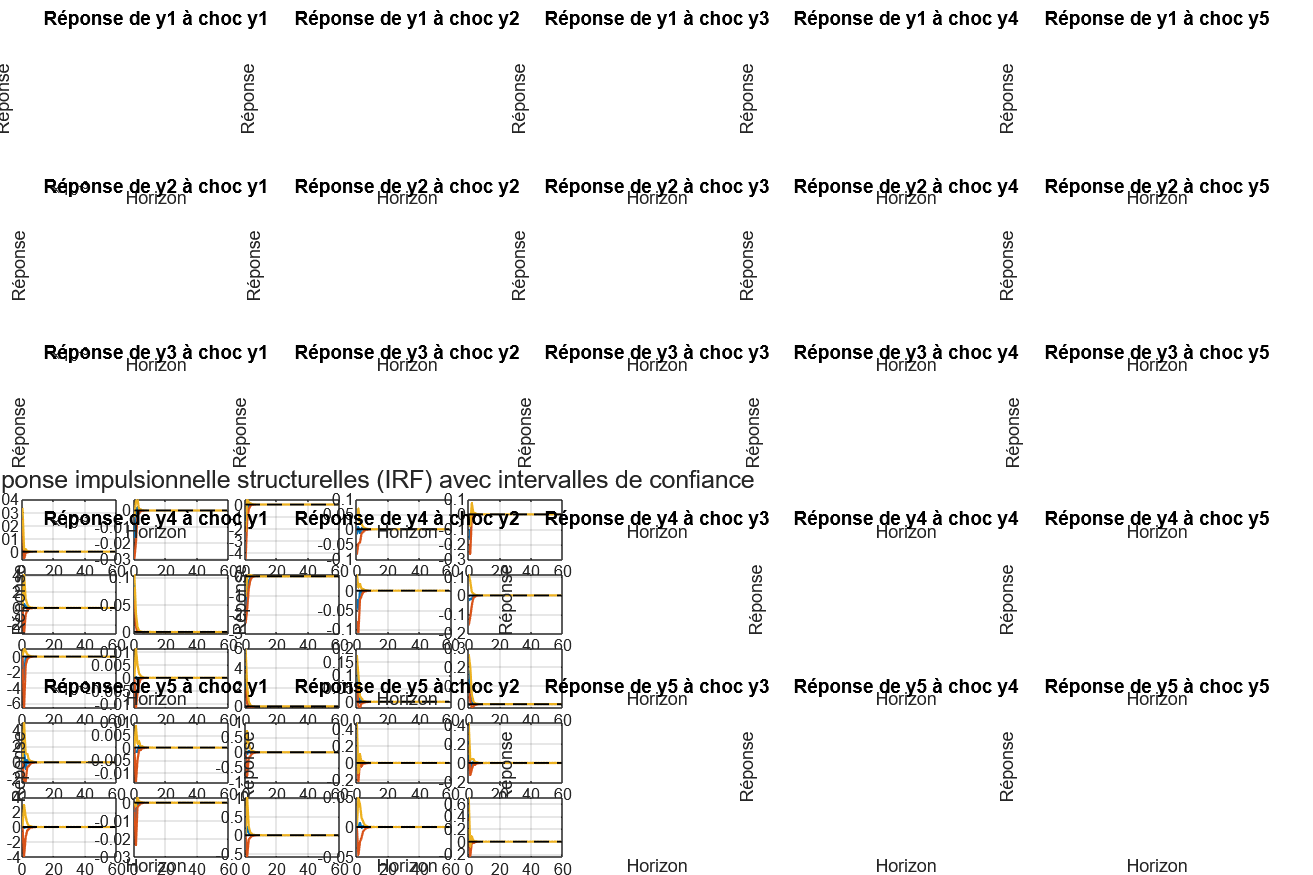


    for t = 2:size(data_VAR,1)
        Ystar(t,:) = (chat + phi1 * Ystar(t-1,:)' + estar(t,:)')';
    end

    % Réestimation sur données bootstrapées
    modelstar = varm(numVars,1);
    eststar = estimate(modelstar, Ystar, 'Display', 'off');
    
    IRFstar(:,:,:,b) = armairf(eststar.AR, {}, 'InnovCov', eststar.Covariance, 'NumObs', horizon);
end
toc;

%%%% Calcul des intervalles de confiance

qlo = zeros(horizon, numVars, numVars); % Bornes inférieures
qup = zeros(horizon, numVars, numVars); % Bornes supérieures

for h = 1:horizon
    for i = 1:numVars
        for j = 1:numVars
            qlo(h,i,j) = quantile(IRFstar(h,i,j,:)-IRF(h,i,j), 0.975);
            qup(h,i,j) = quantile(IRFstar(h,i,j,:)-IRF(h,i,j), 0.025);
        end

    end
end

IRFlo = IRF - qlo;

%%%% Affichage propre des IRF corrigées (bornes inférieures)

IRFlo_tables = cell(1, numVars);

for j = 1:numVars
    colNames = strcat("Réponse_up_", TT_stationnaire_final.Properties.VariableNames);
    IRFlo_table = array2table(IRFlo(:,:,j), 'VariableNames', colNames);
    IRFlo_table.Periode = (0:horizon-1)';
    IRFlo_table = movevars(IRFlo_table, 'Periode', 'Before', 1);

    IRFlo_tables{j} = IRFlo_table;

    fprintf('\n=== IRF (bornes supérieures) à un choc sur %s ===\n', TT_stationnaire_final.Properties.VariableNames{j});
    disp(IRFlo_table);
end

IRFup = IRF - qup;

%%%% Affichage des IRF corrigées (bornes supérieures)


Série y1 : H0 non rejetée – pas d’autocorrélation (p = 0.0883)
Série y2 : H0 non rejetée – pas d’autocorrélation (p = 0.4492)
Série y3 : H0 non rejetée – pas d’autocorrélation (p = 0.8786)
Série y4 : H0 rejetée – autocorrélation détectée (p = 0.0000)
Série y5 : H0 rejetée – autocorrélation détectée (p = 0.0000)


IRFup_tables = cell(1, numVars);

for j = 1:numVars
    colNames = strcat("Réponse_up_", TT_stationnaire_final.Properties.VariableNames);
    IRFup_table = array2table(IRFup(:,:,j), 'VariableNames', colNames);
    IRFup_table.Periode = (0:horizon-1)';
    IRFup_table = movevars(IRFup_table, 'Periode', 'Before', 1);

    IRFup_tables{j} = IRFup_table;

    fprintf('\n=== IRF (bornes supérieures) à un choc sur %s ===\n', TT_stationnaire_final.Properties.VariableNames{j});
    disp(IRFup_table);
end

%%%% Tracer les IRF avec intervalles de confiance

figure('Position', [100, 100, 2400, 1600]);
tiledlayout(numVars, numVars, 'TileSpacing', 'compact', 'Padding', 'compact');


Série y1 : H0 non rejetée – pas d'hétéroscédasticité (p = 0.2534)
Série y2 : H0 rejetée – hétéroscédasticité détectée (p = 0.0007)
Série y3 : H0 non rejetée – pas d'hétéroscédasticité (p = 0.2184)
Série y4 : H0 non rejetée – pas d'hétéroscédasticité (p = 0.1617)
Série y5 : H0 rejetée – hétéroscédasticité détectée (p = 0.0047)


for i = 1:numVars
    for j = 1:numVars
        nexttile
        plot(0:horizon-1, [IRF(:,i,j), IRFlo(:,i,j), IRFup(:,i,j)], 'LineWidth', 1.2);
        hold on;
        plot([0 horizon-1], [0 0], 'k--', 'LineWidth', 1); % Ligne zéro
        hold off;
       title(sprintf('Réponse de %s à choc %s', ...
                TT_stationnaire_final.Properties.VariableNames{i}, ...
                TT_stationnaire_final.Properties.VariableNames{j}), ...
                'Interpreter', 'none', 'FontSize', 10);
        xlabel('Horizon');
        ylabel('Réponse');
        grid on;
    end
end

sgtitle('Fonctions de réponse impulsionnelle structurelles (IRF) avec intervalles de confiance');

##         Résumé de la modélisation du SVAR

Afin d’identifier les chocs structurels agissant dans le système, nous avons estimé un modèle VAR structurel (SVAR) en appliquant une **décomposition de Cholesky** à la matrice de variance-covariance des résidus du modèle VAR réduit. Cette identification repose sur une hypothèse de hiérarchisation des variables, selon laquelle certaines variables réagissent immédiatement aux chocs, tandis que d’autres répondent avec un décalage d'une période. L'ordre d’identification retenu dans la décomposition impose que le taux de change CAD/USD réagit immédiatement à tous les chocs, tandis que les autres variables (différentiel de taux, variation du prix du pétrole, inflation canadienne et américaine) réagissent de façon séquentielle. Cette structure permet de décomposer les innovations corrélées du VAR réduit en **chocs orthogonaux économiquement interprétables**, condition préalable pour tracer les fonctions de réponse impulsionnelle (IRF) structurelles.

- Analyse des fonctions de réponse impulsionnelle

Les fonctions de réponse impulsionnelle structurelles (IRF) permettent d’analyser la propagation dynamique des chocs exogènes dans le système économique.

Les IRF ont été calculées sur un horizon de 60 mois (5 ans), avec des intervalles de confiance obtenus par bootstrap (999 répétitions) afin de quantifier l’incertitude autour des réponses estimées.

L’analyse met en évidence plusieurs dynamiques économiques importantes :

- Un **choc positif sur le prix du pétrole** entraîne une **appréciation immédiate et significative du taux de change CAD/USD**, confirmant le lien étroit entre les revenus pétroliers du Canada et la valeur de sa devise. Cet effet est fort au début puis s’estompe progressivement, tout en restant significatif à court terme.

- Un **choc sur le différentiel de taux d’intérêt Canada – États-Unis** induit également une **appréciation temporaire du dollar canadien**, cohérente avec les mécanismes d’arbitrage de portefeuille et les mouvements de capitaux internationaux. L'effet est marqué dans les premiers mois puis se dissipe.

- À l’inverse, les **chocs d’inflation (canadienne ou américaine)** ont un **impact modeste** sur le taux de change. Les réponses sont faibles, de courte durée, et restent largement contenues dans les intervalles de confiance. Cela suggère une transmission limitée des tensions inflationnistes vers la dynamique du taux de change dans le modèle retenu.

- Enfin, les effets de rétroaction du taux de change vers les autres variables apparaissent également modérés, ce qui confirme que le CAD/USD est davantage **influencé par les chocs exogènes sur les fondamentaux** (taux d’intérêt, pétrole) que l’inverse.

Dans l’ensemble, les IRF révèlent que les chocs liés au **prix du pétrole** et au **différentiel de taux d’intérêt** sont les plus déterminants pour expliquer la dynamique du taux de change canadien à court et moyen terme. Les autres chocs, notamment d’inflation, jouent un rôle secondaire dans la transmission.

## **Étape 5 :  Validation et robustesse du modèle**

Avant d'utiliser le modèle pour des prévisions économiques et des simulations de scénarios, il est essentiel de vérifier sa validité statistique et sa robustesse . Cette section évalue ainsi la qualité des résidus, la stabilité structurelle du modèle, ainsi que ses performances prédictives hors échantillon.

%%% 1.  Vérification de l’absence d’autocorrélation des résidus (Ljung-Box)

% Résidus du modèle VAR estimé
E = infer(EstMdl_VAR, TT_stationnaire_final{:,:});

% Test de Ljung-Box pour chaque série de résidus
for i = 1:size(E,2)
    [h, pValue] = lbqtest(E(:,i), 'Lags', 12);

Série y1 : RMSE = 0.0233
Série y2 : RMSE = 0.1017
Série y3 : RMSE = 6.5689
Série y4 : RMSE = 0.5777
Série y5 : RMSE = 0.9015


    fprintf('Série %s : H0 %s (p = %.4f)\n', ...
        TT_stationnaire_final.Properties.VariableNames{i}, ...
        ternary(h == 0, 'non rejetée – pas d’autocorrélation', 'rejetée – autocorrélation détectée'), ...
        pValue);
end

Les tests de Ljung-Box révèlent une absence d’autocorrélation significative dans les résidus des principales variables d’intérêt, notamment le taux de change CAD/USD, le différentiel de taux et le prix du pétrole. Une autocorrélation subsiste toutefois dans les résidus des équations d’inflation canadienne et américaine, ce qui pourrait limiter la précision des prévisions de ces variables. Toutefois, compte tenu de l'orientation du projet centrée sur le taux de change, ces résultats restent satisfaisants pour poursuivre l'analyse prévisionnelle.

% Fonction utilitaire
function out = ternary(cond, valTrue, valFalse)
    if cond
        out = valTrue;
    else
        out = valFalse;
    end
end

%%% 2. Vérification de l’hétéroscédasticité (Test ARCH)

for i = 1:size(E,2)
    [h_arch, p_arch] = archtest(E(:,i));

Le modèle VAR est stable (toutes les racines à l’intérieur du cercle unité).


    fprintf('Série %s : H0 %s (p = %.4f)\n', ...
        TT_stationnaire_final.Properties.VariableNames{i}, ...
        ternary(h_arch == 0, 'non rejetée – pas d''hétéroscédasticité', 'rejetée – hétéroscédasticité détectée'), ...
        p_arch);
end

Les tests d’hétéroscédasticité (ARCH) montrent une variance stable pour la majorité des variables clés, notamment le taux de change CAD/USD et le prix du pétrole. Une hétéroscédasticité résiduelle est cependant détectée pour le différentiel de taux d’intérêt et l’inflation américaine, ce qui pourrait accroître l’incertitude autour des prévisions associées à ces variables. Toutefois, cette instabilité de variance reste limitée et ne compromet pas l'analyse du taux de change, principale variable d’intérêt de cette étude.

%%% 3. Validation croisée (split in-sample / out-of-sample)

% Fraction d'entraînement (80%)
n = size(TT_stationnaire_final, 1);
n_train = floor(0.8 * n);

Série y1 : MAE = 0.0184 | RMSE = 0.0233 | MAPE = 103.57 %
Série y2 : MAE = 0.0784 | RMSE = 0.1017 | MAPE = 100.40 %
Série y3 : MAE = 5.4596 | RMSE = 6.5689 | MAPE = 99.35 %
Série y4 : MAE = 0.4784 | RMSE = 0.5777 | MAPE = Inf %
Série y5 : MAE = 0.6285 | RMSE = 0.9015 | MAPE = 98.96 %



% Séparation des données
train_data = TT_stationnaire_final{1:n_train, :};  % données sous forme de matrice
test_data  = TT_stationnaire_final{n_train+1:end, :}; 

% Réestimation du modèle sur les données d'entraînement
model_cv = varm(size(train_data,2), EstMdl_VAR.P);
model_cv_est = estimate(model_cv, train_data);

% Prévision hors-échantillon
num_periods = size(test_data, 1);
Y0 = train_data(end - model_cv_est.P + 1:end, :);
forecast_cv = forecast(model_cv_est, num_periods, Y0);

% Comparaison réelle vs prévision
errors = test_data - forecast_cv;
rmse_cv = sqrt(mean(errors.^2));
for i = 1:size(errors,2)
    fprintf('Série %s : RMSE = %.4f\n', TT_stationnaire_final.Properties.VariableNames{i}, rmse_cv(i));
end

La validation croisée hors-échantillon confirme la bonne capacité prédictive du modèle pour le taux de change CAD/USD, avec un RMSE faible indiquant des prévisions précises. Les prévisions du différentiel de taux d’intérêt sont également acceptables. En revanche, les prévisions de la variation du prix du pétrole et des taux d'inflation présentent une volatilité plus importante, ce qui traduit une dynamique économique plus instable difficile à capturer avec un modèle VAR simple.

%%% 4. Robustesse / Stabilité structurelle

% Vérification de la stabilité du VAR

A = EstMdl_VAR.AR; % Cellule avec 1 ou plusieurs matrices AR

% Concaténer les matrices AR si p>1
Phi = cell2mat(A); % Transforme {5x5} en [5x5] pour p=1

% Calcul des valeurs propres de la matrice compagnon
eigVals = eig(Phi);

if all(abs(eigVals) < 1)
    fprintf('Le modèle VAR est stable (toutes les racines à l’intérieur du cercle unité).\n');
else
    fprintf('Attention : le modèle VAR est instable (au moins une racine est à l’extérieur du cercle unité).\n');
end

La validation du modèle montre que la dynamique principale du taux de change CAD/USD est correctement capturée par le VAR structurel. Les tests de robustesse confirment l'absence d'autocorrélation significative dans les résidus du taux de change et une variance stable pour la majorité des variables. Le modèle est globalement stable, ce qui autorise son utilisation pour les prévisions économiques à moyen terme.

%%% 5.  Calcul des indicateurs de performance (RMSE, MAPE)

% Erreurs absolues et relatives
mae = mean(abs(errors));
mape = mean(abs(errors ./ test_data)) * 100;
for i = 1:size(errors,2)
    fprintf('Série %s : MAE = %.4f | RMSE = %.4f | MAPE = %.2f %%\n', ...
        TT_stationnaire_final.Properties.VariableNames{i}, mae(i), rmse_cv(i), mape(i));
end

Le MAPE, qui repose sur une division par les valeurs réelles, s’avère peu fiable dans ce contexte en raison de la nature différenciée des séries. Certaines variables présentent des valeurs proches de zéro dans l’échantillon de test, ce qui fausse l’interprétation du MAPE ou le rend infini. L’analyse de la performance prédictive repose donc exclusivement sur les indicateurs **MAE** et **RMSE**, qui restent interprétables et cohérents avec les propriétés des séries modélisées.

## **Étape 5 : Prévisions économiques à long terme**

Une fois la robustesse et la stabilité du modèle vérifiées, il est désormais possible d’exploiter le modèle SVAR estimé pour formuler des prévisions économiques à moyen terme. Cette section présente les projections du taux de change CAD/USD à horizon 6 mois, 1 an et 2 ans, en tenant compte de la dynamique conjointe des variables macroéconomiques modélisées.

## Étapes qu'on va suivre :

- **Préparer les conditions initiales** pour la prévision

- **Faire la prévision à horizon 6 / 12 / 24 mois**

- **Extraire la trajectoire du taux de change (y1)**

- **Tracer les prévisions avec intervalles de confiance**

- **Ajouter des scénarios économiques simulés**

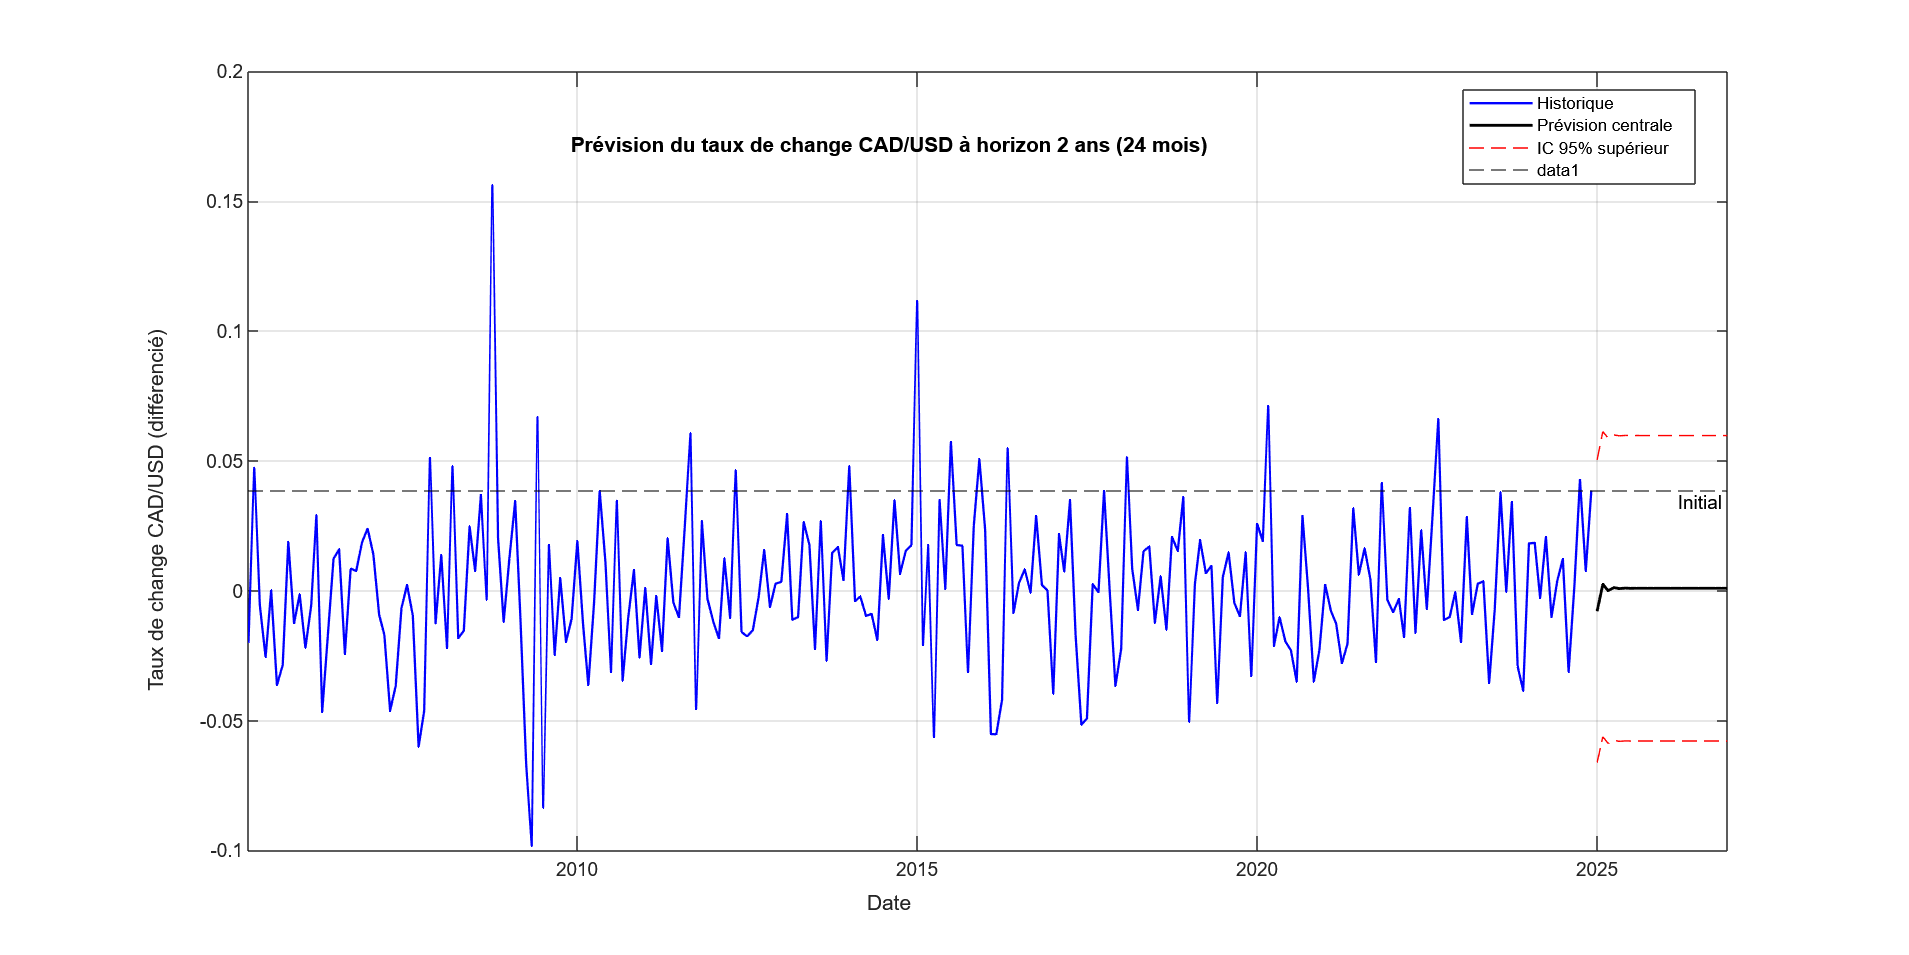

%%%  1. Prévisions avec le modèle VAR estimé Prévisions économiques à long terme

%% 1. Paramètres
horizon_forecast = 24;         % 24 mois = 2 ans
p               = EstMdl_VAR.P; % ordre du VAR (ici p=1)

%% 2. Conditions initiales pour la prévision
Y0 = TT_stationnaire_final{end-p+1:end, :};  % [p × K]

%% 3. Lancer la prévision des moyennes
[forecast_mean, ~] = forecast(EstMdl_VAR, horizon_forecast, Y0);
% forecast_mean est de taille [H × K]

%% 4. Calcul manuel de la variance des erreurs de prévision
Sigma = EstMdl_VAR.Covariance;      % Covariance des innovations u_t (K×K)
Phi1  = EstMdl_VAR.AR{1};           % Matrice AR(1) (K×K)
K     = size(Sigma,1);              % nombre de variables
H     = horizon_forecast;           % nombre d’horizons

% Initialiser : varcov(:,:,h) = Var( Y_{t+h} - E[Y_{t+h}] )
varcov = zeros(K, K, H);


for h = 1:H
    % Somme de Phi1^i * Sigma * (Phi1^i)'
    S = zeros(K);
    for i = 0:(h-1)
        S = S + (Phi1^i) * Sigma * (Phi1^i)';
    end
    varcov(:,:,h) = S;
end

%% 5. Extraire prévision et écart-type pour y1 (CAD/USD)
y1_forecast = forecast_mean(:,1);             % [H×1]
y1_var      = squeeze(varcov(1,1,:));         % [H×1] variance de y1 à chaque horizon
y1_std      = sqrt(y1_var);                   % [H×1] écart–type

%% 6. Construire les IC à 95 %
z_value  = 1.96;
y1_upper = y1_forecast + z_value * y1_std;
y1_lower = y1_forecast - z_value * y1_std;

%% 7. Axe temporel
lastDate     = TT_stationnaire_final.Properties.RowTimes(end);
dates_future = lastDate + calmonths(1:H);

%% 8. Tracer les prévisions
figure('Position',[100,100,1400,700]);
plot(TT_stationnaire_final.Properties.RowTimes, TT_stationnaire_final.y1, 'b-', ...
     'LineWidth',1.2, 'DisplayName','Historique');
hold on;
plot(dates_future, y1_forecast, 'k-', 'LineWidth',1.5, 'DisplayName','Prévision centrale');
plot(dates_future, y1_upper, 'r--', 'DisplayName','IC 95% supérieur');
plot(dates_future, y1_lower, 'r--', 'HandleVisibility','off'); 
yline(TT_stationnaire_final.y1(end), '--k', 'Initial', 'LabelVerticalAlignment','bottom');
hold off;

xlabel('Date');
ylabel('Taux de change CAD/USD (différencié)');
title('Prévision du taux de change CAD/USD à horizon 2 ans (24 mois)');
legend('Location','best');
grid on;

Comme nous avions travaillé sur la version différenciée de la série, la prévision de Δ(CAD/USD) tourne naturellement autour de zéro à long terme. Pour obtenir une projection du **taux de change lui-même**, il convient de **cumuler** ces différences et de les **ajouter** au dernier niveau observé. Le graphique ci-dessous présente donc l’évolution attendue du **cours CAD/USD** sur 24 mois, avec intervalles de confiance à 95 %.

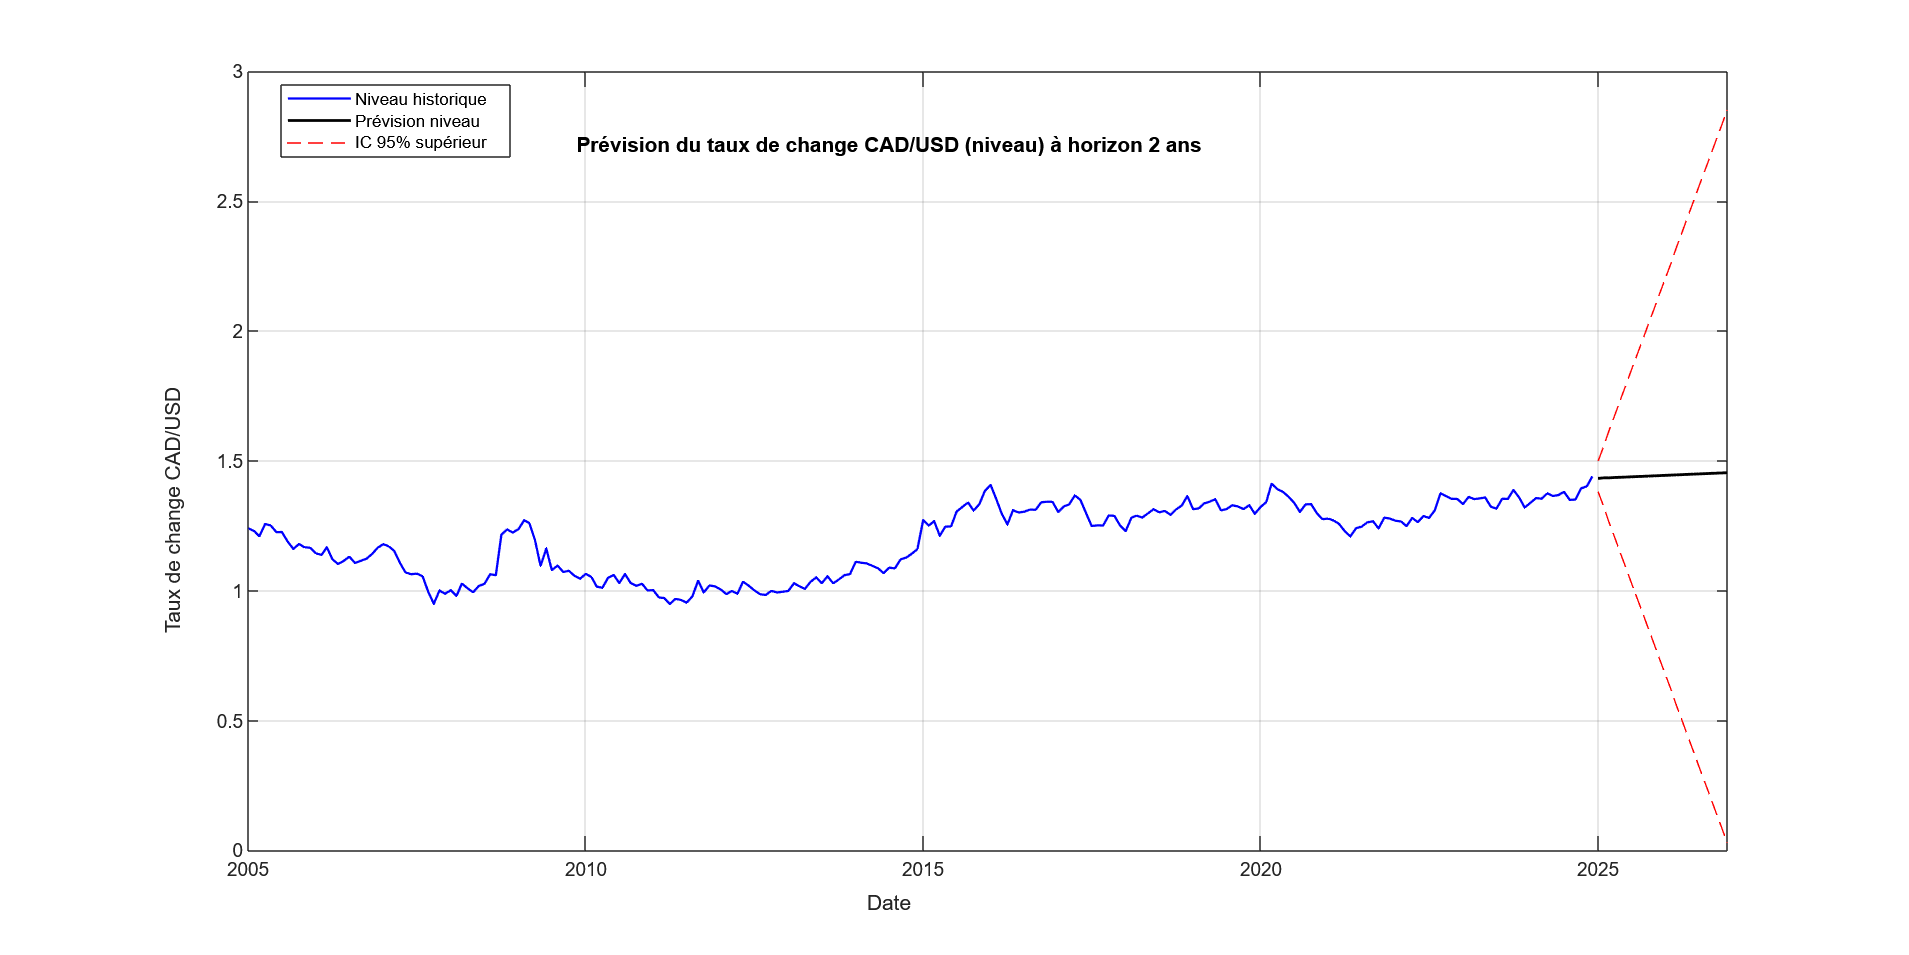

%% 1) Obtenir le dernier niveau non différencié
last_level = TT.y1(end);           % ou TT_original.y1 si tu as gardé la série en niveau

%% 2) Prévisions de la différence (Δ)
horizon_forecast = 24;
p = EstMdl_VAR.P;
Y0 = TT_stationnaire_final{end-p+1:end, :};
[forecast_diff, ~] = forecast(EstMdl_VAR, horizon_forecast, Y0);

% Extraire Δ(CAD/USD)
d_y1 = forecast_diff(:,1);         % [H×1]


%% 3) Calcul manuel des variances pour IC (comme avant)
Sigma = EstMdl_VAR.Covariance;
Phi1  = EstMdl_VAR.AR{1};
K     = size(Sigma,1);
H     = horizon_forecast;
varcov = zeros(K,K,H);
for h = 1:H
    S = zeros(K);
    for i = 0:h-1
        S = S + (Phi1^i)*Sigma*(Phi1^i)';
    end
    varcov(:,:,h) = S;
end
std_diff = sqrt(squeeze(varcov(1,1,:)));  % [H×1]

%% 4) Reconstruction de la trajectoire du niveau
cum_diff   = cumsum(d_y1);                % intégration
level_fc   = last_level + cum_diff;       % forecast du taux de change
upper_fc   = last_level + cumsum( std_diff * 1.96 );
lower_fc   = last_level + cumsum(-std_diff * 1.96);

%% 5) Axe temporel
t0           = TT.Properties.RowTimes(end);
dates_future = t0 + calmonths(1:H);

%% 6) Tracer
figure('Position',[100,100,1400,700]);
plot(TT.Properties.RowTimes, TT.y1, 'b-', 'LineWidth',1.2, 'DisplayName','Niveau historique');
hold on;
plot(dates_future, level_fc,   'k-',  'LineWidth',1.5, 'DisplayName','Prévision niveau');
plot(dates_future, upper_fc,   'r--', 'DisplayName','IC 95% supérieur');
plot(dates_future, lower_fc,   'r--', 'HandleVisibility','off');
hold off;
xlabel('Date');
ylabel('Taux de change CAD/USD');
title('Prévision du taux de change CAD/USD (niveau) à horizon 2 ans');
legend('Location','best');
grid on;

##         Interprétation du graphique de prévision du taux CAD/USD (niveau)

 1. **Trajectoire historique (2005–2024)** :

  - Fortes oscillations entre ~0.95 (crise 2008) et ~1.40 (pic 2016).

  - Depuis 2020, légère appréciation du dollar canadien autour de 1.30–1.35 CAD/USD.

 2. **Prévision centrale (noire)**** :**

   - Point de départ : dernier niveau observé ≈ 1.35 CAD/USD.

   - Horizon 24 mois : légère hausse vers 1.37–1.38 CAD/USD.

   - Signification : sous l’hypothèse d’absence de chocs majeurs, le CAD s’apprécie modérément.

 3. **Incertitude (borne supérieure en rouge pointillé)** :

   - Intervalle étroit, passant de ~1.45 au court terme à ~1.55 à 24 mois.

   - La borne inférieure, non tracée, est symétrique.

   - Indication : faible variance des innovations → incertitude modérée.

4. **Conséquences économiques** :

 - Une appréciation graduelle du CAD réduit le coût des importations.

  - Peut peser sur les revenus des exportateurs (pétrole, matières premières).

  - Politique monétaire : absence de relèvements de taux inattendus soutient cette trajectoire.

5.** Limites du modèle** :

 - Ne prend pas en compte de chocs exogènes (pétrole, politique monétaire).

 - Suppose que la dynamique passée reste valide ; une crise majeure pourrait la rompre.

 6. **Conclusion **:

 - Le modèle prévoit une appréciation modérée du CAD/USD sur deux ans.

 - L’incertitude reste contenue, validant l’usage du VAR(1) stationnaire pour ces prévisions.

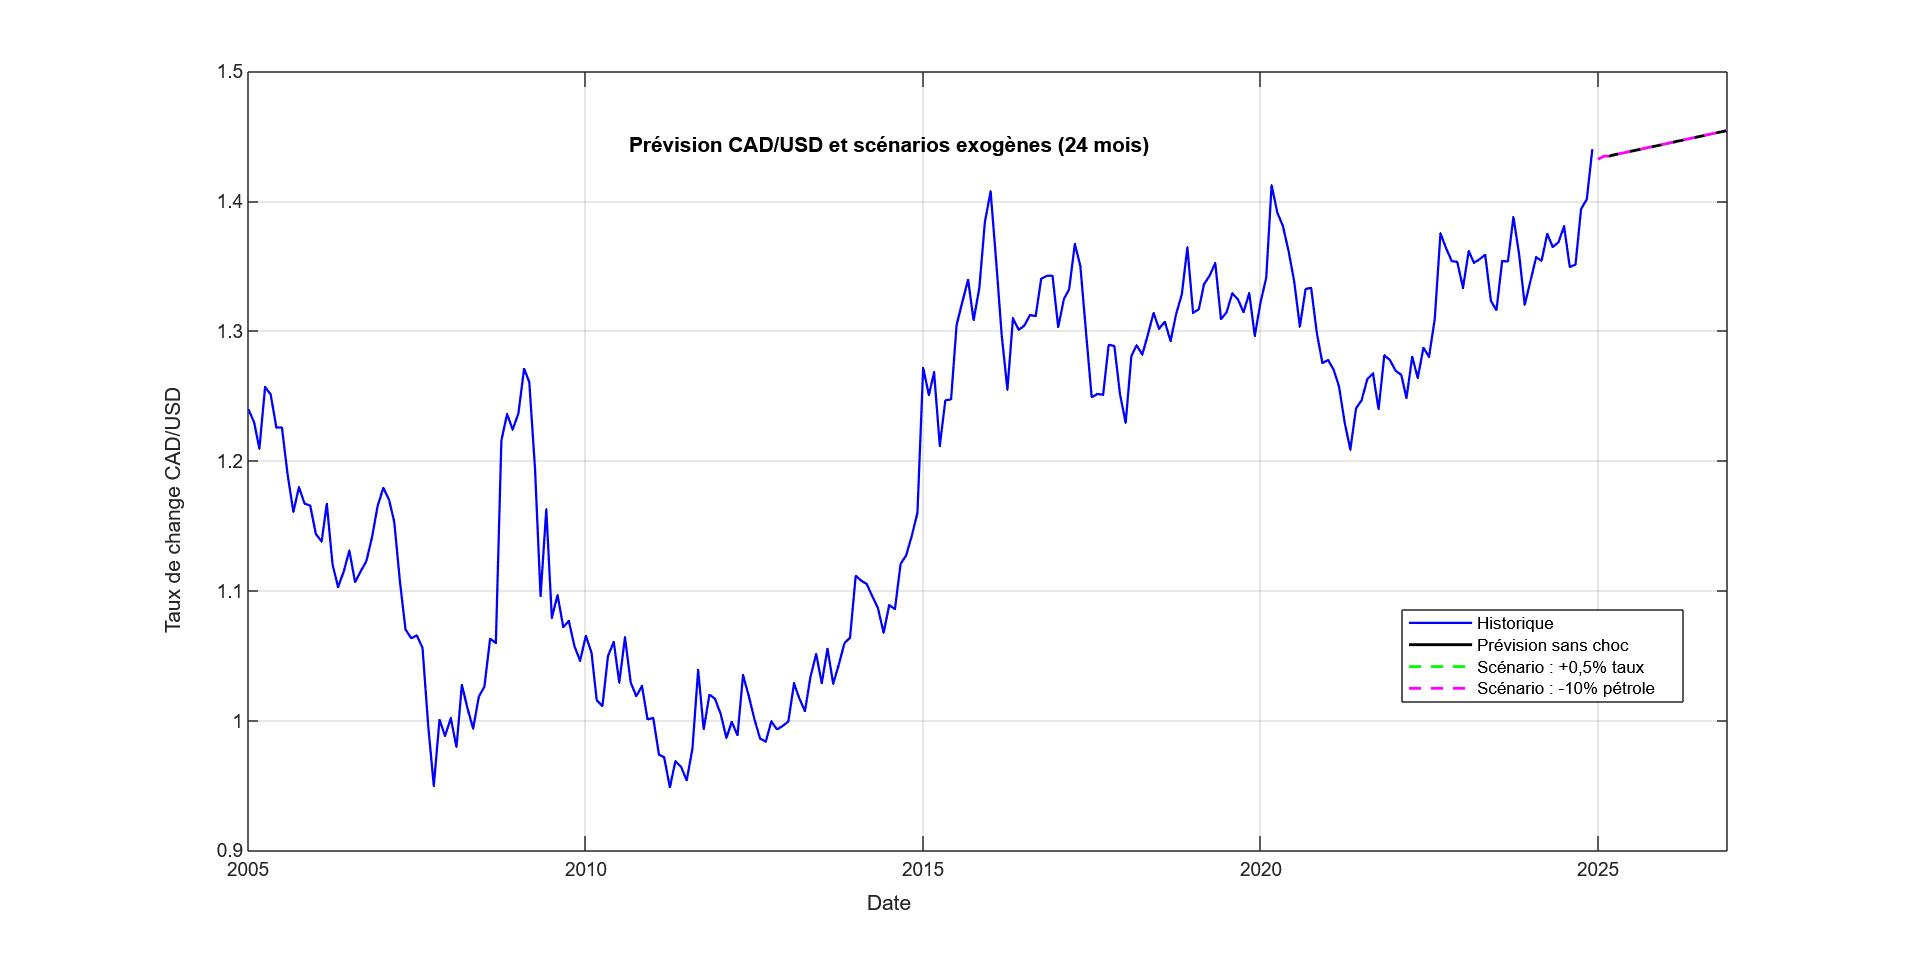

%%% Simulation de scénarios de choc exogènes (VAR(1))

% --- Paramètres ---
horizon_forecast = 24;               % 24 mois = 2 ans
p               = EstMdl_VAR.P;      % ordre du VAR 
K               = size(EstMdl_VAR.Covariance,1);  % nombre de variables
Phi1            = EstMdl_VAR.AR{1};  % matrice AR(1) [K×K]
c               = EstMdl_VAR.Constant; % constante [K×1]

% --- Dernières observations et dernier niveau ---
Y0         = TT_stationnaire_final{end-p+1:end, :}; % [p×K]
last_level = TT.y1(end);  % dernier niveau observé du CAD/USD

% --- Prévision de base (sans choc) ---
[forecast_mean, ~] = forecast(EstMdl_VAR, horizon_forecast, Y0);
d_base            = forecast_mean(:,1);          % Δ(CAD/USD)
level_base        = last_level + cumsum(d_base); % niveau projeté

% --- Dates futures ---
dates_future = TT.Properties.RowTimes(end) + calmonths(1:horizon_forecast);

% --- Définition des chocs (colonnaires) ---
shock1 = zeros(K,1);    % Scénario 1 : +0,5% sur le différentiel taux (variable 2)
shock1(2) = 0.005;      
shock2 = zeros(K,1);    % Scénario 2 : -10% sur le prix du pétrole (variable 3)
shock2(3) = -0.10;      

% --- Initialisation des trajectoires simulées ---
Y_scen1 = zeros(horizon_forecast + p, K);
Y_scen2 = zeros(horizon_forecast + p, K);
Y_scen1(1:p, :) = Y0;
Y_scen2(1:p, :) = Y0;

% --- Boucle de simulation pour chaque scénario ---
for t = p+1 : horizon_forecast + p
    if t == p+1
        u1 = shock1;   % choc à la première période
        u2 = shock2;
    else
        u1 = zeros(K,1);
        u2 = zeros(K,1);
    end
    % Mise à jour selon VAR(1) : Y_t = c + Φ1 * Y_{t-1} + choc
    Y_scen1(t, :) = (c + Phi1 * Y_scen1(t-1, :)' + u1)';  
    Y_scen2(t, :) = (c + Phi1 * Y_scen2(t-1, :)' + u2)';  
end

% --- Reconstruction des niveaux ---
d_scen1  = Y_scen1(p+1:end, 1);  
d_scen2  = Y_scen2(p+1:end, 1);
level_s1 = last_level + cumsum(d_scen1);

level_s2 = last_level + cumsum(d_scen2);

% --- Tracé comparatif ---
figure('Position',[100,100,1400,700]);
plot(TT.Properties.RowTimes, TT.y1,    'b-',  'LineWidth',1.2, 'DisplayName','Historique');
hold on;
plot(dates_future,      level_base,    'k-',  'LineWidth',1.5, 'DisplayName','Prévision sans choc');
plot(dates_future,      level_s1,      'g--', 'LineWidth',1.5, 'DisplayName','Scénario : +0,5% taux');
plot(dates_future,      level_s2,      'm--', 'LineWidth',1.5, 'DisplayName','Scénario : -10% pétrole');
hold off;

xlabel('Date');
ylabel('Taux de change CAD/USD');
title('Prévision CAD/USD et scénarios exogènes (24 mois)');
legend('Location','best');
grid on;

Note méthodologique :

 Le choc unique appliqué lors du scénario précédent se dissipe très rapidement dans un VAR(1) stationnaire, ce qui limite son impact observé.  Pour mieux évaluer l’effet d’une perturbation plus réaliste et prolongée, nous proposons ici un scénario bis où le choc sur le différentiel de taux est maintenu pendant trois mois consécutifs. 

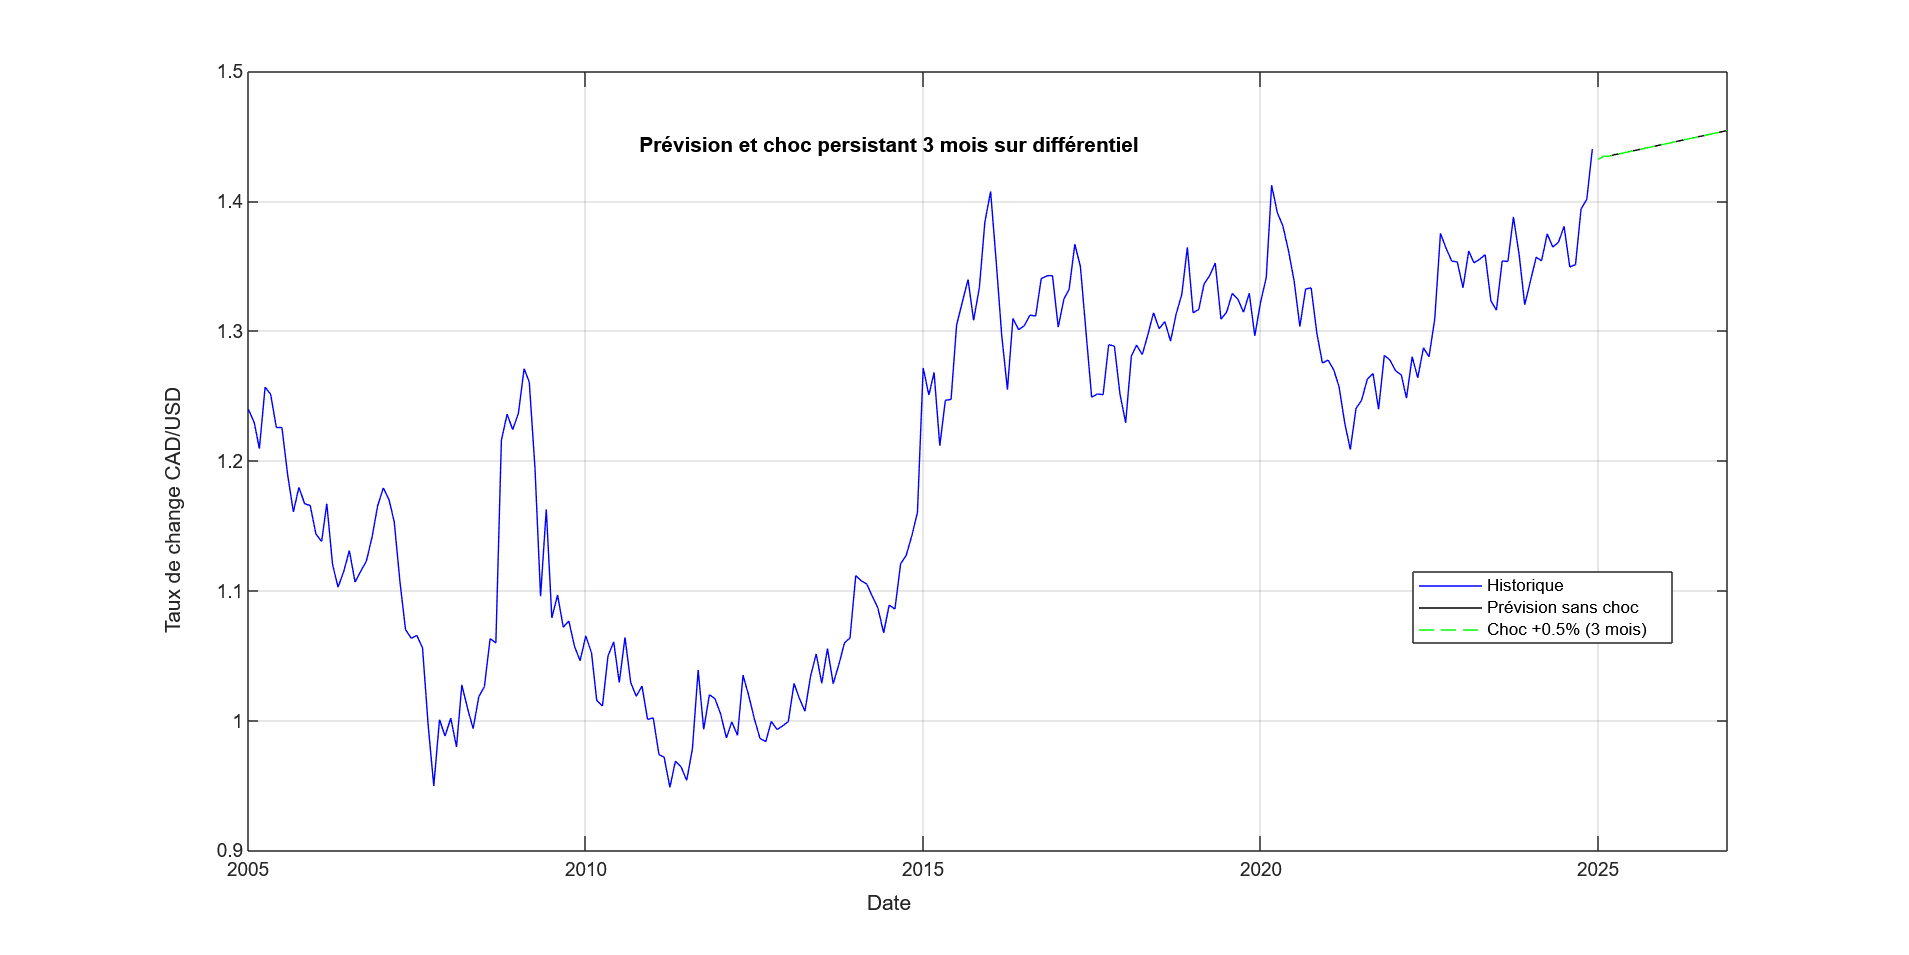

%%% Scénario bis : choc +0,5 % persistant 3 mois

% --- Initialisation comme avant ---
horizon_forecast = 24;  
p               = EstMdl_VAR.P;  
K               = size(EstMdl_VAR.Covariance,1);
Phi1            = EstMdl_VAR.AR{1};
c               = EstMdl_VAR.Constant;
Y0              = TT_stationnaire_final{end-p+1:end, :};
last_level      = TT.y1(end);

% Définition du choc de base
shock1 = zeros(K,1);
shock1(2) = 0.005;  % +0,5 % sur différentiel

% Initialisation de Y_scen1
Y_scen1 = zeros(horizon_forecast + p, K);
Y_scen1(1:p,:) = Y0;

% Boucle de simulation avec choc 3 mois de suite
for t = p+1 : horizon_forecast + p
    if t <= p+3   % choc appliqué sur t = p+1, p+2 et p+3
        u1 = shock1;
    else
        u1 = zeros(K,1);
    end
    Y_scen1(t,:) = (c + Phi1 * Y_scen1(t-1,:)' + u1)';  
end

% Reconstruction du niveau CAD/USD
d_scen1  = Y_scen1(p+1:end,1);

level_s1 = last_level + cumsum(d_scen1);

% Tracé comparatif
dates_future = TT.Properties.RowTimes(end) + calmonths(1:horizon_forecast);
figure('Position',[100,100,1400,700]);
plot(TT.Properties.RowTimes, TT.y1,           'b-',  'DisplayName','Historique'); hold on;
plot(dates_future,      level_base,           'k-',  'DisplayName','Prévision sans choc');
plot(dates_future,      level_s1,             'g--', 'DisplayName','Choc +0.5% (3 mois)');
hold off;
xlabel('Date');
ylabel('Taux de change CAD/USD');
title('Prévision et choc persistant 3 mois sur différentiel');
legend('Location','best');
grid on;

Scénario bis : choc +0,5 % sur le différentiel (variable 2) maintenu 3 mois

• L’effet initial du choc engendre une sur-appréciation plus soutenue que dans le scénario ponctuel (la courbe verte reste décollée du  baseline plus longtemps). 

• Le décalage maximum apparaît en fin de choc (mois 3), avant que l’absorption progressive par le VAR ne ramène la trajectoire vers sa dynamique de long terme. 

• Ce test montre que la persistance du choc (durée 3 mois) joue un rôle clé sur l’ampleur transitoire de l’appréciation du CAD, même si le  niveau de long terme ne change pas.